## Optical Pumping

### Task 1 v1.2

#### Goal: numerically model energy level splitting of ground state of $^{87}Rb$ and $^{85}Rb$ in external magnetic field

#### Introduction

Time independen Shrodinger equation:


$$\hat{H}|\Psi\rangle = E|\Psi\rangle$$


H - Hamiltonian of the system

E - energy states of the system, also an eigenvalue of H

In our case H is composed of two components:

$\hat{H} = \hat{H_{B}} + \hat{H_{hf}}$,

where

$\hat{H_B} - $Hamiltonian term due to applied external magnetic field

$\hat{H_{hf}} - $Hamiltonian term due to interaction of nuclear and electron spins

#### **Magnetic field interaction Hamiltonian**

Assuming that that the atom behaves just like a simple dipole we determine that the most dominant term in the  $$\hat{H_{B}}$$ is:

$\hat{H_B} = -\hat{\vec{\mu}} \vec{B} = -\frac{\mu_B}{\hbar}(g_S \hat{\vec{S}} + g_I \hat{\vec{I}}) \dot{} \vec{B}$,

where


$$\mu_B = \frac{e\hbar}{2m_e}$$


#### **Hyperfine Interaction Hamiltonian**

Interaction between the spin of the electron and nuclear spin


$$\hat{H}_{hf} = a_{hf} (\hat{S}_x\hat{I}_x + \hat{S}_y\hat{I}_y + \hat{S}_z\hat{I}_z)$$


This hamiltonian term can be written as $\textbf{S} \cdot \textbf{I}$ which results is a new quantum number that is ranges from $|S-I|$ up to $S+I$ in integer steps. 

In our scenario we have: $S = 1/2$ and $I = 3/2$ for $^{87}Rb$ and $I = 5/2$ for $^{85}Rb$. 

The total number of states is given by the following equation: $(2S + 1)(2I+1)$.

#### **Converting Hamiltonian operators into Matrix form**

**Step 1:** Lets chose a set of basis vectors and express $\hat{H}$as a matrix. This way we can numerically solve for the energy states of the system. 

**Step 1.1:** First, lets simplify the $\hat{H}_B$. Lets assume that our magnetic field is in the direction of the z axis (z axis is of the atom is an arbitrary term, so we just pick z axis to be in line with magnetic field). Let $\vec{B} = B_0\hat{z}$. Now we get:


$$\hat{H}_B = \frac{\mu_B}{\hbar}\left(g_S\hat{S}_z +  g_S\hat{I}_z)$$


Since our Hamiltonian ($\hat{H}_B$) is expressed in terms of $\hat{S}_z $ and $\hat{I}_z$ we should should use the eigenvectors of these operators. These eigenvectors are:

$|S, m_S \rangle \otimes |I, m_I \rangle = |m_S, m_I \rangle$, or

Then, 


$$\hat{H}_B|m_S, m_I\rangle = \mu_BB_0(g_Sm_S+g_Im_I)|m_S, m_I\rangle$$



$$\langle m'_S, m'_I|\hat{H}_B|m_S, m_I\rangle = \mu_BB_0(g_Sm_S+g_Im_I)\delta_{{m_S}, {m'_S}}\delta_{{m_I}, {m'_I}}$$


$m_S$ and $m_I$ are quantum numbers that are defined and calculated later.

$\hat{H}_B$ in this basis is a diagonal matrix.

**Analytical expresion for the linear Zeeman effect.**

In weak field conditions,the difference in energy levels due to Zeemer effect can be analytically calculated by the following formula:


$$\Delta E_{|F m_f\rangle} = \mu_Bm_Fg_FB_z$$


where,

$m_F$ is a quantum number that represents the components of the elctron spin along the B field

$g_F $ is the factor for an interaction between magnetic field and a nucleous

$g_F $ depend on the quantum number F, as well whether we are dealing with $^{85}Rb$ or $^{87}Rb$:

For the ground state of $^{85}Rb$


$$g_{F=2} = -1/3\\
g_{F=3} = 1/3$$


For the ground state of $^{87}Rb$


$$g_{F=2} = -1/2\\
g_{F=3} = 1/2$$


$m_S$ and $m_I$ are quantum numbers that are defined and calculated later.

**Step 1.2 : Calculating H**$\hat{H}_{hf}$ 

The hyperfine term is not diagonal in this basis, however we can represent it as follows:


$$\left\langle m_{S}^{\prime}, m_{I}^{\prime}\left|S_{+} I_{-}\right| m_{S}, m_{I}\right\rangle=\hbar^{2} \sqrt{\left(S-m_{S}\right)\left(S+m_{S}+1\right)\left(I+m_{I}\right)\left(I-m_{I}+1\right)} \delta_{m_{S}+1, m_{S}^{\prime}} \delta_{m_{I}-1, m_{I}^{\prime}}$$



$$\left\langle m_{S}^{\prime}, m_{I}^{\prime}\left|S_{-} I_{+}\right| m_{S}, m_{I}\right\rangle=\hbar^{2} \sqrt{\left(S+m_{S}\right)\left(S-m_{S}+1\right)\left(I-m_{I}\right)\left(I+m_{I}+1\right)} \delta_{m_{S}-1, m_{S}^{\prime}} \delta_{m_{I}+1, m_{I}^{\prime}}$$



$$\left\langle m_{S}^{\prime}, m_{I}^{\prime}\left|\hat{S}_{z} \hat{I}_{z}\right| m_{S}, m_{I}\right\rangle=\hbar^{2} m_{S} m_{I} \delta_{m_{S}, m_{S}^{\prime}} \delta_{m_{I}, m_{I}^{\prime}}$$


**1.3: Determining the quantum numners **$m_S$** and **$m_I
$ 

Following the rules of addition of angular momentum we can determine the quantum numbers for all possible states:


$$^{\textbf{85}}\textbf{Rb}$$



$$|\frac{1}{2}, m_S \rangle \otimes |\frac{5}{2}, m_I \rangle = |m_S, m_I \rangle$$


The quantum numnder m ranges from 3 down to 2 and all the possible states are: 

The following ordering of the states also represents the index of appearence of this terms in Hamiltonian


$$|3, 3 \rangle = |m_S=1/2, m_I=5/2 \rangle\\\,
|3, 2 \rangle = |m_S=1/2, m_I=3/2 \rangle\\\,
|3, 1 \rangle = |m_S=1/2, m_I=1/2 \rangle\\\, 
|3, 0 \rangle = |m_S=1/2, m_I=-1/2 \rangle\\\, 
|3, -1 \rangle = |m_S=1/2, m_I=-3/2 \rangle\\\, 
|3, -2 \rangle = |m_S=1/2, m_I=-5/2 \rangle\\\,
|3, -3 \rangle = |m_S=-1/2, m_I=-5/2 \rangle\\\,
|2, 2 \rangle = |m_S=-1/2, m_I=5/2 \rangle\\\,
|2, 1 \rangle = |m_S=-1/2, m_I=3/2 \rangle\\\,
|2, 0 \rangle = |m_S=-1/2, m_I=1/2 \rangle\\\,
|2, -1 \rangle = |m_S=-1/2, m_I=-1/2 \rangle\\\,
|2, -2 \rangle = |m_S=-1/2, m_I=-3/2 \rangle$$


In total there are 12 states.


$$^{\textbf{87}}\textbf{Rb}$$



$$|\frac{1}{2}, m_S \rangle \otimes |\frac{3}{2}, m_I \rangle = |m_S, m_I \rangle$$


The quantum numnder m ranges from 2 down to 1 and all the possible states are: 


$$|2, 2 \rangle = |m_S=1/2, m_I=3/2 \rangle\\\,
|2, 1 \rangle = |m_S=1/2, m_I=1/2 \rangle\\\,
|2, 0 \rangle = |m_S=1/2, m_I=-1/2 \rangle\\\,
|2, -1 \rangle = |m_S=1/2, m_I=-3/2 \rangle\\\,
|2, -2 \rangle = |m_S=-1/2, m_I=-3/2 \rangle\\\,
|1, 1 \rangle = |m_S=-1/2, m_I=3/2 \rangle\\\,
|1, 0 \rangle = |m_S=-1/2, m_I=1/2 \rangle\\\,
|1, -1 \rangle = |m_S=-1/2, m_I=-1/2 \rangle$$


In total there are 8 states. 

### Beginning of calculations

#### Define global variables that are required for calculations

global h_bar h g_S g_I_85 g_I_87 mu_b mu_0 s_e i_n_87 i_n_85 a_87_S_1_2 a_87_P_1_2 a_85_S_1_2 a_85_P_1_2;

h_bar = 6.5821189916*(10^(-16));    % Reduced Planck's constant [eV*s]
h = 2*pi*h_bar;                     % Planks constant [eV*s]

g_S = 2.002319304362215;            % Electron spin g factor
g_I_85 = -0.0002936400060;          % 85Rb Nuclear g factor
g_I_87 = -0.000995141410;           % 87Rb Nuclear g factor

mu_b = h*1.39962460435*10^6;        % Bohr magneton [eV*s][Hz/G]
mu_0 = 4*pi*10^(-7);                % permiability of free space [N/A^2]

s_e = 1/2;                          % spin of the electron
i_n_87 = 3/2;                       % spin of the 87 Rb nucleus
i_n_85 = 5/2;                       % spin of the 85 Rb nucleus

a_87_S_1_2 = h*3.41734130545214545*(10^9)/h_bar^2; % hyperefine interaction constant for ground state of 87Rb [Hz]/[eV*s]^2
a_87_P_1_2 = h*407.2563*10^6/h_bar^2;              % hyperefine interaction constant for 1st excited state of 87Rb [Hz]/[eV*s]^2

a_85_S_1_2 = h*1.011910813020*(10^9)/h_bar^2;      % hyperefine interaction constant for ground state of 85Rb [Hz]/[eV*s]^2
a_85_P_1_2 = h*120.52756*(10^6)/h_bar^2;           % hyperefine interaction constant for 1st excited state of 87Rb [Hz]/[eV*s]^2

a_hf_85 = a_85_S_1_2;
a_hf_87 = a_87_S_1_2;

#### **Calculating **$\hat{H}_B$

This is trivial, since it is diagonal in this basis - function for calculation is defined at the end of the Live script.

#### Calculating $\hat{H}_{hf}$ for $^{\textbf{85}}\textbf{Rb}$:

global H_hf_85;                     % define global empty matrices
H_hf_85 = zeros(12, 12);            % define an empty matrix for 85Rb

For the term $S_+I_-$ from all the possible cross terms the only non zero ones are the ones that obey the following equation:


$$m_S+1=m'_S\\
m_I-1 = m'_I$$


These work out to be:


$$\langle{m_S'=1/2, m_I'=3/2}|S_+I_-|m_S=-1/2, m_I=5/2\rangle: H_{hf}(2,8)\\\,
\langle{m_S'=1/2, m_I'=1/2}|S_+I_-|m_S=-1/2, m_I=3/2\rangle: H_{hf}(3,9)\\\,
\langle{m_S'=1/2, m_I'=-1/2}|S_+I_-|m_S=-1/2, m_I=1/2\rangle: H_{hf}(4,10)\\\,
\langle{m_S'=1/2, m_I'=-3/2}|S_+I_-|m_S=-1/2, m_I=-1/2\rangle: H_{hf}(5,11)\\\,
\langle{m_S'=1/2, m_I'=-5/2}|S_+I_-|m_S=-1/2, m_I=-3/2\rangle: H_{hf}(6,12)$$


Now that we have the $m_s$ and $m_l
$ values, as well as matrix indecies we can start filling up the Hamiltonian

% lets calculate the S+I- components
index_row = 6;
index_col = 12;

% m_s value is constant for these spin states
m_s = -1/2;
I = i_n_85;
for index=-3/2:5/2
    H_hf_85(index_row, index_col) = (h_bar^2)*a_hf_85*0.5*sqrt((s_e-m_s)*(s_e+m_s+1)*(I+index)*(I-index+1)); % unit analysis [eV*s]^2 [eV*s][Hz]/[eV*s]^2 = [eV]
    index_row = index_row - 1;
    index_col = index_col - 1;
end

For the term $S_-I_+$ from all the possible cross terms the only non zero ones are the ones that obey the following equation:


$$m_S-1=m'_S\\
m_I+1 = m'_I$$


These are:


$$\langle{m_S'=-1/2, m_I'=5/2}|S_+I_-|m_S=1/2, m_I=3/2\rangle: H_{hf}(8,2)\\\,
\langle{m_S'=-1/2, m_I'=3/2}|S_+I_-|m_S=1/2, m_I=1/2\rangle: H_{hf}(9,3)\\\,
\langle{m_S'=-1/2, m_I'=1/2}|S_+I_-|m_S=1/2, m_I=-1/2\rangle: H_{hf}(10,4)\\\,
\langle{m_S'=-1/2, m_I'=-1/2}|S_+I_-|m_S=1/2, m_I=-3/2\rangle: H_{hf}(11,5)\\\,
\langle{m_S'=-1/2, m_I'=-3/2}|S_+I_-|m_S=1/2, m_I=-5/2\rangle: H_{hf}(12,6)$$


index_row = 12;
index_col = 6;
m_s = 1/2;
I = i_n_85;
for index=-5/2:3/2
    H_hf_85(index_row, index_col) = (h_bar^2)*a_hf_85*0.5*sqrt((s_e+m_s)*(s_e-m_s+1)*(I-index)*(I+index+1));
    index_row = index_row - 1;
    index_col = index_col - 1;
end

For the term $S_zI_z$ the terms are in the diagonak of the matrix:

% define the 2D array of m_S and m_I values
m = [[1/2, 5/2]; [1/2, 3/2]; [1/2, 1/2]; [1/2, -1/2]; [1/2, -3/2]; [1/2, -5/2]; [-1/2,-5/2]; [-1/2, 5/2]; [-1/2, 3/2]; [-1/2, 1/2]; [-1/2, -1/2]; [-1/2, -3/2]]';
index = 1;
for s = m
    H_hf_85(index, index) = (h_bar^2)*a_hf_85*s(1)*s(2);
    index = index + 1;
end

### Calculating $\hat{H}_{hf}$ for $^{\textbf{87}}\textbf{Rb}$:

global H_hf_87;
H_hf_87 = zeros(8, 8);

Similarly, we calculate term $S_+I_-$ from all the possible cross terms:


$$\langle{m_S'=1/2, m_I'=1/2}|S_+I_-|m_S=-1/2, m_I=3/2\rangle: H_{hf}(2,6)\\\,
\langle{m_S'=1/2, m_I'=-1/2}|S_+I_-|m_S=-1/2, m_I=1/2\rangle: H_{hf}(3,7)\\\,
\langle{m_S'=1/2, m_I'=-3/2}|S_+I_-|m_S=-1/2, m_I=-1/2\rangle: H_{hf}(4,8)$$


index_row = 4;
index_col = 8;
m_s = -1/2;
I = i_n_87;
for index=-1/2:3/2
    H_hf_87(index_row, index_col) = (h_bar^2)*a_hf_87*0.5*sqrt((s_e-m_s)*(s_e+m_s+1)*(I+index)*(I-index+1));
    index_row = index_row - 1;
    index_col = index_col - 1;
end

For the term $S_-I_+$ from all the possible cross terms the only non zero ones are:


$$\langle{m_S'=-1/2, m_I'=3/2}|S_+I_-|m_S=1/2, m_I=1/2\rangle: H_{hf}(6,2)\\\,
\langle{m_S'=-1/2, m_I'=1/2}|S_+I_-|m_S=1/2, m_I=-1/2\rangle: H_{hf}(7,3)\\\,
\langle{m_S'=-1/2, m_I'=-1/2}|S_+I_-|m_S=1/2, m_I=-3/2\rangle: H_{hf}(8,4)$$


index_row = 8;
index_col = 4;
m_s = 1/2;
I = i_n_87;
for index=-3/2:1/2
    H_hf_87(index_row, index_col) = (h_bar^2)*a_hf_87*0.5*sqrt((s_e+m_s)*(s_e-m_s+1)*(I-index)*(I+index+1));
    index_row = index_row - 1;
    index_col = index_col - 1;
end

For the term $S_zI_z$

m = [[1/2, 3/2]; [1/2, 1/2]; [1/2, -1/2]; [1/2, -3/2]; [-1/2, -3/2]; [-1/2, 3/2]; [-1/2, 1/2]; [-1/2, -1/2]]';
index = 1;
for s = m
    H_hf_87(index, index) = (h_bar^2)*a_hf_87*s(1)*s(2);
    index = index + 1;
end

## Energy Plots

Calculating energies of the system from full hamiltonian

B = 0:1:2500;                                       % define the span of B values on whiich to compoute energy
energies_85 = [];
energies_87 = [];
h_85 = H_B_mat(B(2500), 85) + H_hf_85            % add Hamiltonian due to hyperfine splitting and Zeemer effect

h_85 = 	1.0e+-4 *

    0.1970         0         0         0         0         0         0         0         0         0         0         0
         0    0.1761         0         0         0         0         0    0.0468         0         0         0         0
         0         0    0.1553         0         0         0         0         0    0.0592         0         0         0
         0         0         0    0.1344         0         0         0         0         0    0.0628         0         0
         0         0         0         0    0.1135         0         0         0         0         0    0.0592         0
         0         0         0         0         0    0.0926         0         0         0         0         0    0.0468
         0         0         0         0         0         0   -0.0924         0         0         0         0         0
         0    0.0468         0         0         0         0         0   -0.1972         0         0         0         0
         0   

for b = 1:length(B)
    h_85 = H_B_mat(B(b), 85) + H_hf_85;             % add Hamiltonian due to hyperfine splitting and Zeemer effect
    h_87 = H_B_mat(B(b), 87) + H_hf_87;             % add Hamiltonian due to hyperfine splitting and Zeemer effect
    
    % by calculating the eigen values of the matrix we can determine energy
    % levels of the syste
    energies_85(b, :) = eig(h_85)/(10^9*h);         % scale by h and devide by a 10^9 to convert to Ghz
    energies_87(b, :) = eig(h_87)/(10^9*h);         % scale by h and devide by a 10^9 to convert to Ghz
end


Calculating energies of the system with linear Zeemer approximation

% - Weak field approximation
energies_85_lz = [];
energies_87_lz = [];
for b = 1:length(B)
    % lets also calculate approximated energies due to linear zeemer
    energy_shift_85 = linear_zeemer(B(b), 85);
    energy_shift_87 = linear_zeemer(B(b), 87);
    energy_shift_87(:,1:3);
    energies_85_lz(b, :) = (eig(H_hf_85) + energy_shift_85')/(10^9*h);
    energies_87_lz(b, :) = (eig(H_hf_87) + energy_shift_87')/(10^9*h);
end

#### Plot energy levels

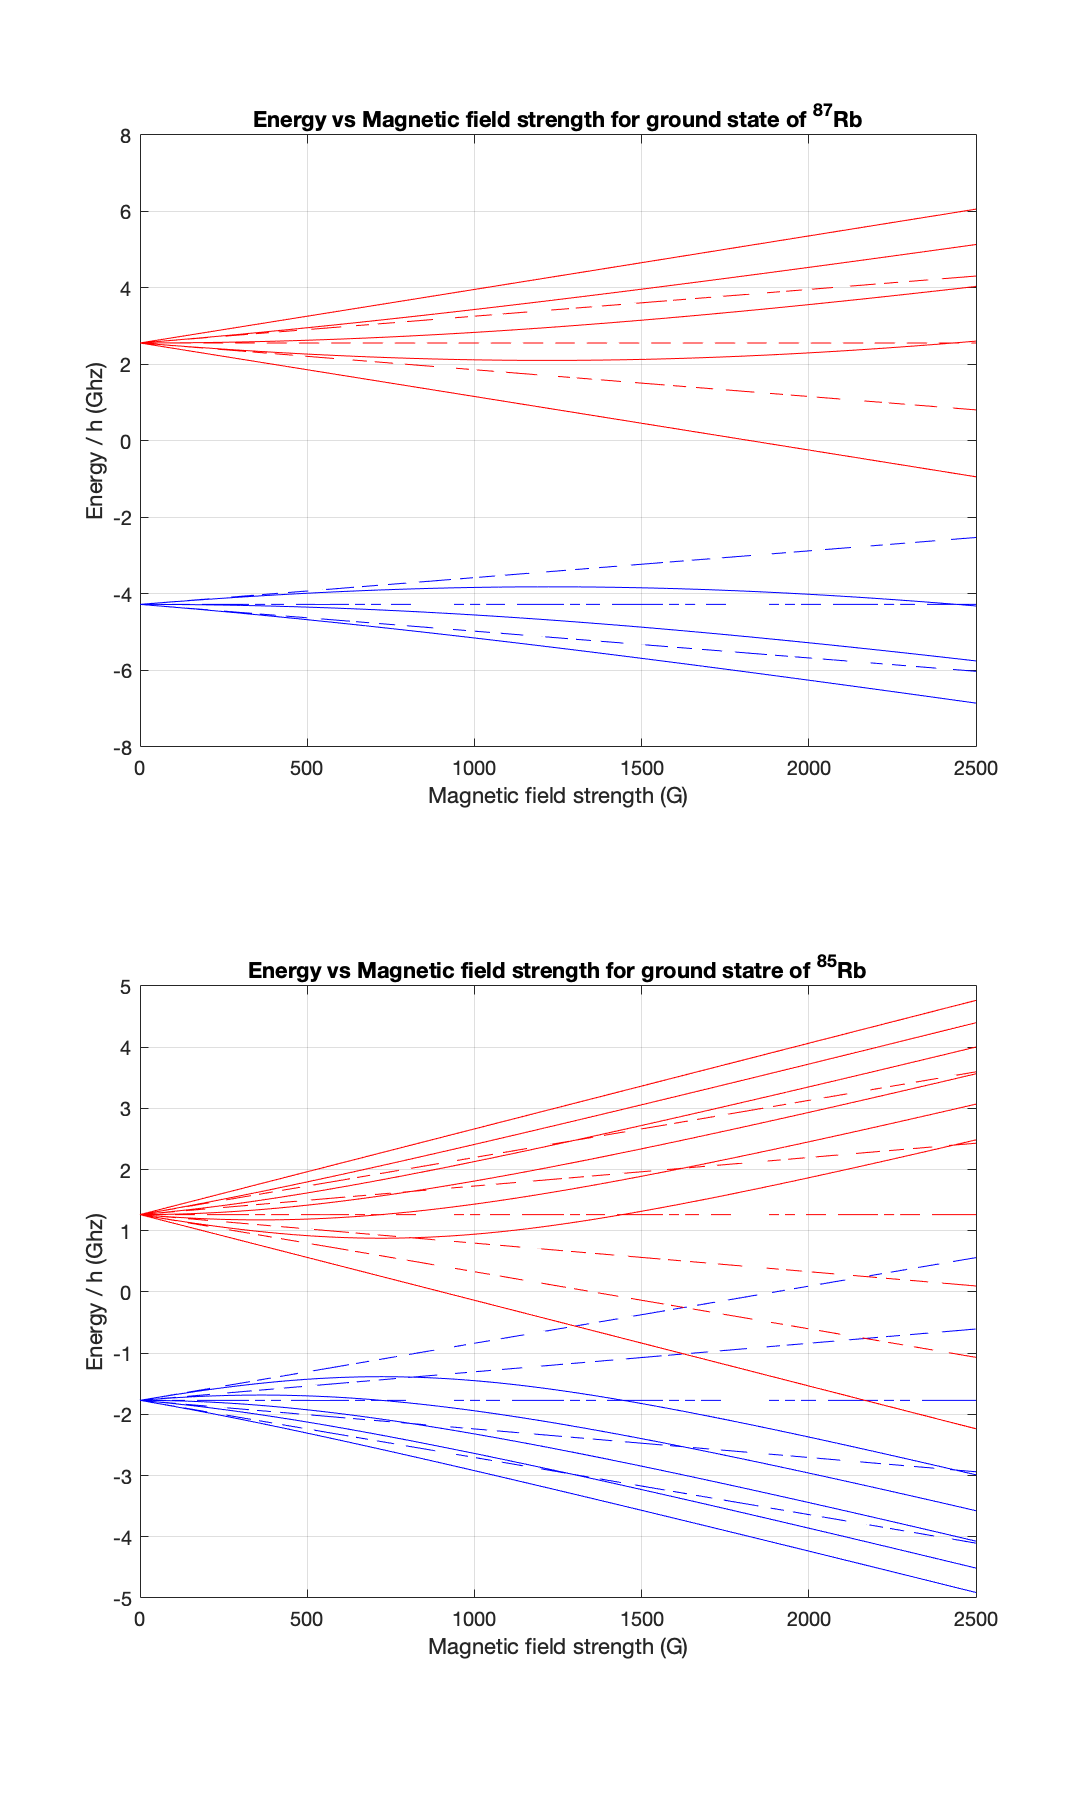

f = figure(1);
set(gcf,'position',[0,0,600,1000]);
subplot(2,1,1); plot(B, energies_87(:,1:3),'b-');
                hold on
                plot(B, energies_87_lz(:,1:3),'b--');
                plot(B, energies_87(:,4:end),"r-");
                plot(B, energies_87_lz(:,4:end),"r--")
title("Energy vs Magnetic field strength for ground state of ^{87}Rb")
xlabel("Magnetic field strength (G)");
ylabel("Energy / h (Ghz)");
grid on
subplot(2,1,2); plot(B, energies_85(:,1:5),'b-');
                hold on
                plot(B, energies_85_lz(:,1:5),'b--');
                plot(B, energies_85(:,6:end),"r-");
                plot(B, energies_85_lz(:,6:end),"r--")
title("Energy vs Magnetic field strength for ground statre of ^{85}Rb");
xlabel("Magnetic field strength (G)");
ylabel("Energy / h (Ghz)");
grid on

**What are the two manifolds? **

The two manifolds are the splitting of two different energy levels of the ground state. Due to the hyper fine structure effects (interaction of nuclear spin with total electron spin), the ground state $^2S_{1/2}$ is split into 2 energy levels (two starting pints on y axis when applied magnetic field is zero). Those two energy levels are represented by the quantum number F, for $^{87}Rb$, F=1 is a red manifold and F=2 in the blue manifold and for $^{85}Rb$, F=2 is a red manifold and F=3. However, when we start applying magnetic field we will produce a Zeemer Effect, which is the further splitting of 2 energy manifolds. The Zeemer effect splits F energy levels in 2F+1 distinc energy levels.

**Can you now identify, in absolute numbers, what “weak” and “strong” magnetic field really means in the context of Rb spectroscopy?** 

In Rb spectroscopy, applied magnetic field is considered to be strong, when the weak field approximation and full analitical solution begin to diverge, in the graph in lab manual,this seems to happen around 100 Gauss.			

### **Finding the RF transition frequencies (**$\Delta M=\pm1, \Delta F=0$**)**

We can calculate transition frequencies with the following formula:


$$\omega = \frac{E_{F,M} - E_{F, M-1}}{\hbar}$$


% linear Zeemer frequencies
omega_85_lz = (energies_85_lz(:, 2:end) - energies_85_lz(:,1:end-1));  % the units are [Mhz]
% remove the value for inbetween F transition
omega_85_lz = [omega_85_lz(:,1:4), omega_85_lz(:,6:end)];              % the units are [Mhz]

omega_87_lz = (energies_87_lz(:, 2:end) - energies_87_lz(:,1:end-1));  % the units are [Mhz]
omega_87_lz = [omega_87_lz(:,1:2), omega_87_lz(:,4:end)];              % the units are [Mhz]

omega_85 = (energies_85(:, 2:end) - energies_85(:,1:end-1));           % the units are [Mhz]
omega_85 = [omega_85(:,1:4), omega_85(:,6:end)];                       % the units are [Mhz]

omega_87 = (energies_87(:, 2:end) - energies_87(:,1:end-1));           % the units are [Mhz]
omega_87 = [omega_87(:,1:2), omega_87(:,4:end)];                       % the units are [Mhz]

Plot the results of cimputation

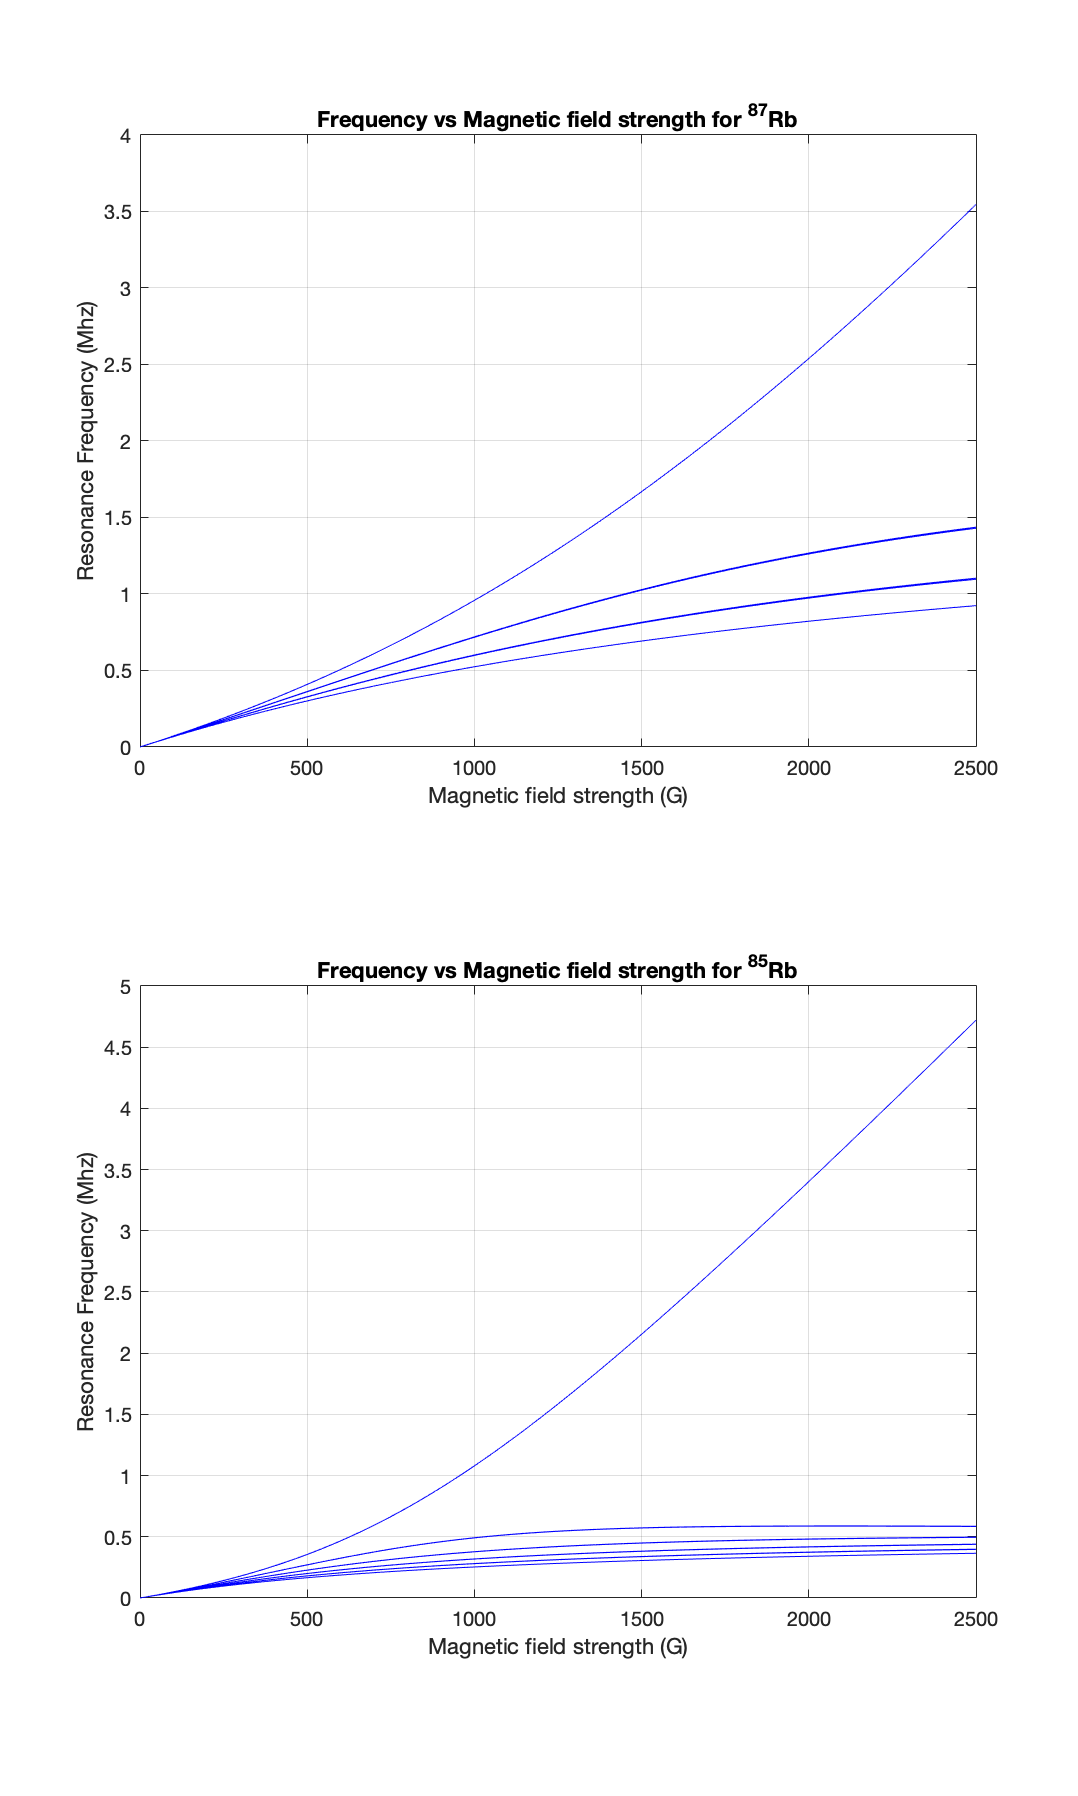

figure();
set(gcf,'position',[0,0,600,1000]);
subplot(2,1,1); plot(B, omega_87,'b-');
%                 hold on
%                 plot(B, omega_87_lz,"r--")
title("Frequency vs Magnetic field strength for ^{87}Rb")
xlabel("Magnetic field strength (G)");
ylabel("Resonance Frequency (Mhz)");
grid on
subplot(2,1,2); plot(B, omega_85,'b-');
%                 hold on
%                 plot(B, omega_85_lz,"r--")
title("Frequency vs Magnetic field strength for ^{85}Rb")
xlabel("Magnetic field strength (G)");
ylabel("Resonance Frequency (Mhz)");
grid on		

Conclusion:

- RF ~ B field for B field strength of <100

- Quadratic RF for B firld strength > 100

### **Weak field regime**

According to the above graph, the transition frequencies are linear with respect to the strength of applied magnetic field B in weak field regine < 100 G.

**We can estimate how many distinct RF resonances we would expect to see in a gas of 85Rb and 87Rb? **

to determine this we should look at the number of distinct frequencies between 2 gases at each magnetic field strength value;

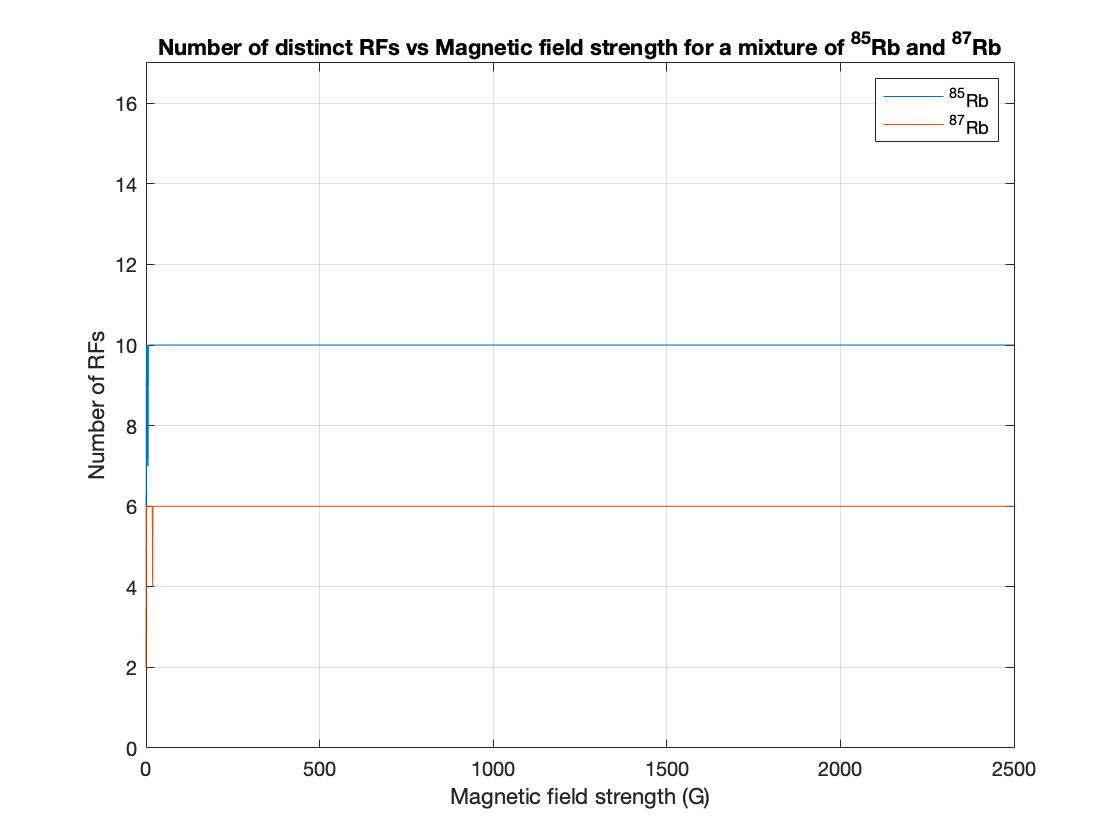

num_of_unique_freq = [];
tolerance = 0.0001;         % [Mhz]
for index = 1:length(B)
    b = B(index);
    freq_85 = uniquetol(omega_85(index,:), tolerance);
    freq_87 = uniquetol(omega_87(index,:), tolerance);
    num_of_unique_freq(index, :) = [length(freq_85); length(freq_87)];
end

figure();
plot(B, num_of_unique_freq(:,1));
hold on
plot(B, num_of_unique_freq(:,2));
legend(["^{85}Rb" "^{87}Rb"])
title("Number of distinct RFs vs Magnetic field strength for a mixture of ^{85}Rb and ^{87}Rb")
xlabel("Magnetic field strength (G)");
ylabel("Number of RFs");
ylim([0 17]);
grid on

#### Conclusion:

- Total 16 frequencies

- 10 from Rb85

- 6 from Rb87

## Task 2 v2

## Goal: determining applied magnetic field by monitoring absorption of a gas mixture of $^{85}Rb $ and $^{87}Rb$

### Lets redefine some constants

clearvars;
global h_bar h g_S g_I_85 g_I_87 mu_b mu_0 s_e i_n_87 i_n_85 a_87_S_1_2 a_87_P_1_2 a_85_S_1_2 a_85_P_1_2;

h_bar = 6.5821189916*(10^(-16));    % Reduced Planck's constant [eV*s]
h = 2*pi*h_bar;                     % Planks constant [eV*s]

g_S = 2.002319304362215;            % Electron spin g factor
g_I_85 = -0.0002936400060;          % 85Rb Nuclear g factor
g_I_87 = -0.000995141410;           % 87Rb Nuclear g factor

mu_b = h*1.39962460435*10^6;        % Bohr magneton [eV*s][Hz/G]
mu_0 = 4*pi*10^(-7);                % permiability of free space [N/A^2]

s_e = 1/2;                          % spin of the electron
i_n_87 = 3/2;                       % spin of the 87 Rb nucleus
i_n_85 = 5/2;                       % spin of the 85 Rb nucleus

a_87_S_1_2 = h*3.41734130545214545*(10^9)/h_bar^2; % hyperefine interaction constant for ground state of 87Rb [Hz]/[eV*s]^2
a_87_P_1_2 = h*407.2563*10^6/h_bar^2;              % hyperefine interaction constant for 1st excited state of 87Rb [Hz]/[eV*s]^2

a_85_S_1_2 = h*1.011910813020*(10^9)/h_bar^2;      % hyperefine interaction constant for ground state of 85Rb [Hz]/[eV*s]^2
a_85_P_1_2 = h*120.52756*(10^6)/h_bar^2;           % hyperefine interaction constant for 1st excited state of 87Rb [Hz]/[eV*s]^2

a_hf_85 = a_85_S_1_2;
a_hf_87 = a_87_S_1_2;

#### Import data files

Weak field regime

% data importing and  file processing
data_folder_low = fullfile("OP3", "LowField");                                                   % data directory relative to the script location

file_numbers =                [38, 39,  41,  42,  44,    45,    47,    48];                      % these are the numbers of files that contain data
frequency_weak_field =   10^3*[80, 100, 140, 160, 300,   600,   1200,  800];                     % frequency of B field in [Hz]
current_main_coil_weak=       [0,  0,   0,   0,   0.052, 0.105, 0.200, 0.200];                   % curent through the main coil in [A] 

[current_sweep_coil_weak, transmission_signal_data_weak] = load_data(data_folder_low, file_numbers);
% plot_current_transmission(frequency_weak_field, current_main_coil_weak, current_sweep_coil_weak, transmission_signal_data_weak, "Weak field");

Strong field regime

data_folder_quad = fullfile("OP3", "Quadratic");                                                    % data directory relative to the script location

file_numbers_quad =               [4, 5,  14,   15,  20,     21,     25,   26];                     % these are the numbers of files that contain data
frequency_quad_field =       10^6*[5.25,  7.85, 6.7, 9.92,  8.31,   12.4,   2.2,  3.1];             % frequency of B field in [Hz]
current_main_coil_quad=           [1.25,  1.25, 1.6, 1.6,   2,      2,      0.5,  0.5];             % curent through the main coil in [A] 

[current_sweep_coil_quad, transmission_signal_data_quad] = load_data(data_folder_quad, file_numbers_quad);

% plot_current_transmission(frequency_quad_field, current_main_coil_quad, current_sweep_coil_quad, transmission_signal_data_quad, "Strong field");		

#### **Determinining the dependence of the resonance frequency on the indicated current in the sweep magnetic coils by using a set of weak-field scans with zero bias field**

% - Get only data with 0 bias current
zero_bias_current_data = current_sweep_coil_weak(1:4,:,:);
zero_bias_transmission_data = transmission_signal_data_weak(1:4,:,:);

% - Get timing data and voltage readings
time = zero_bias_current_data(:,:,1);
current = zero_bias_current_data(:,:,2);
light_transmission = zero_bias_transmission_data(:,:,2);
rf_zero_bias = frequency_weak_field(1:4);

In order to plot the dependence of the resonance frequency on current, we need to first determine the location of the inverse peaks in our data:

First peak will correspond to B=0, which occures at non zero current reading due to ambient magnetic field present along the optical axis, and the other 2 consecutive peaks correspond to different isotopes of Rb.

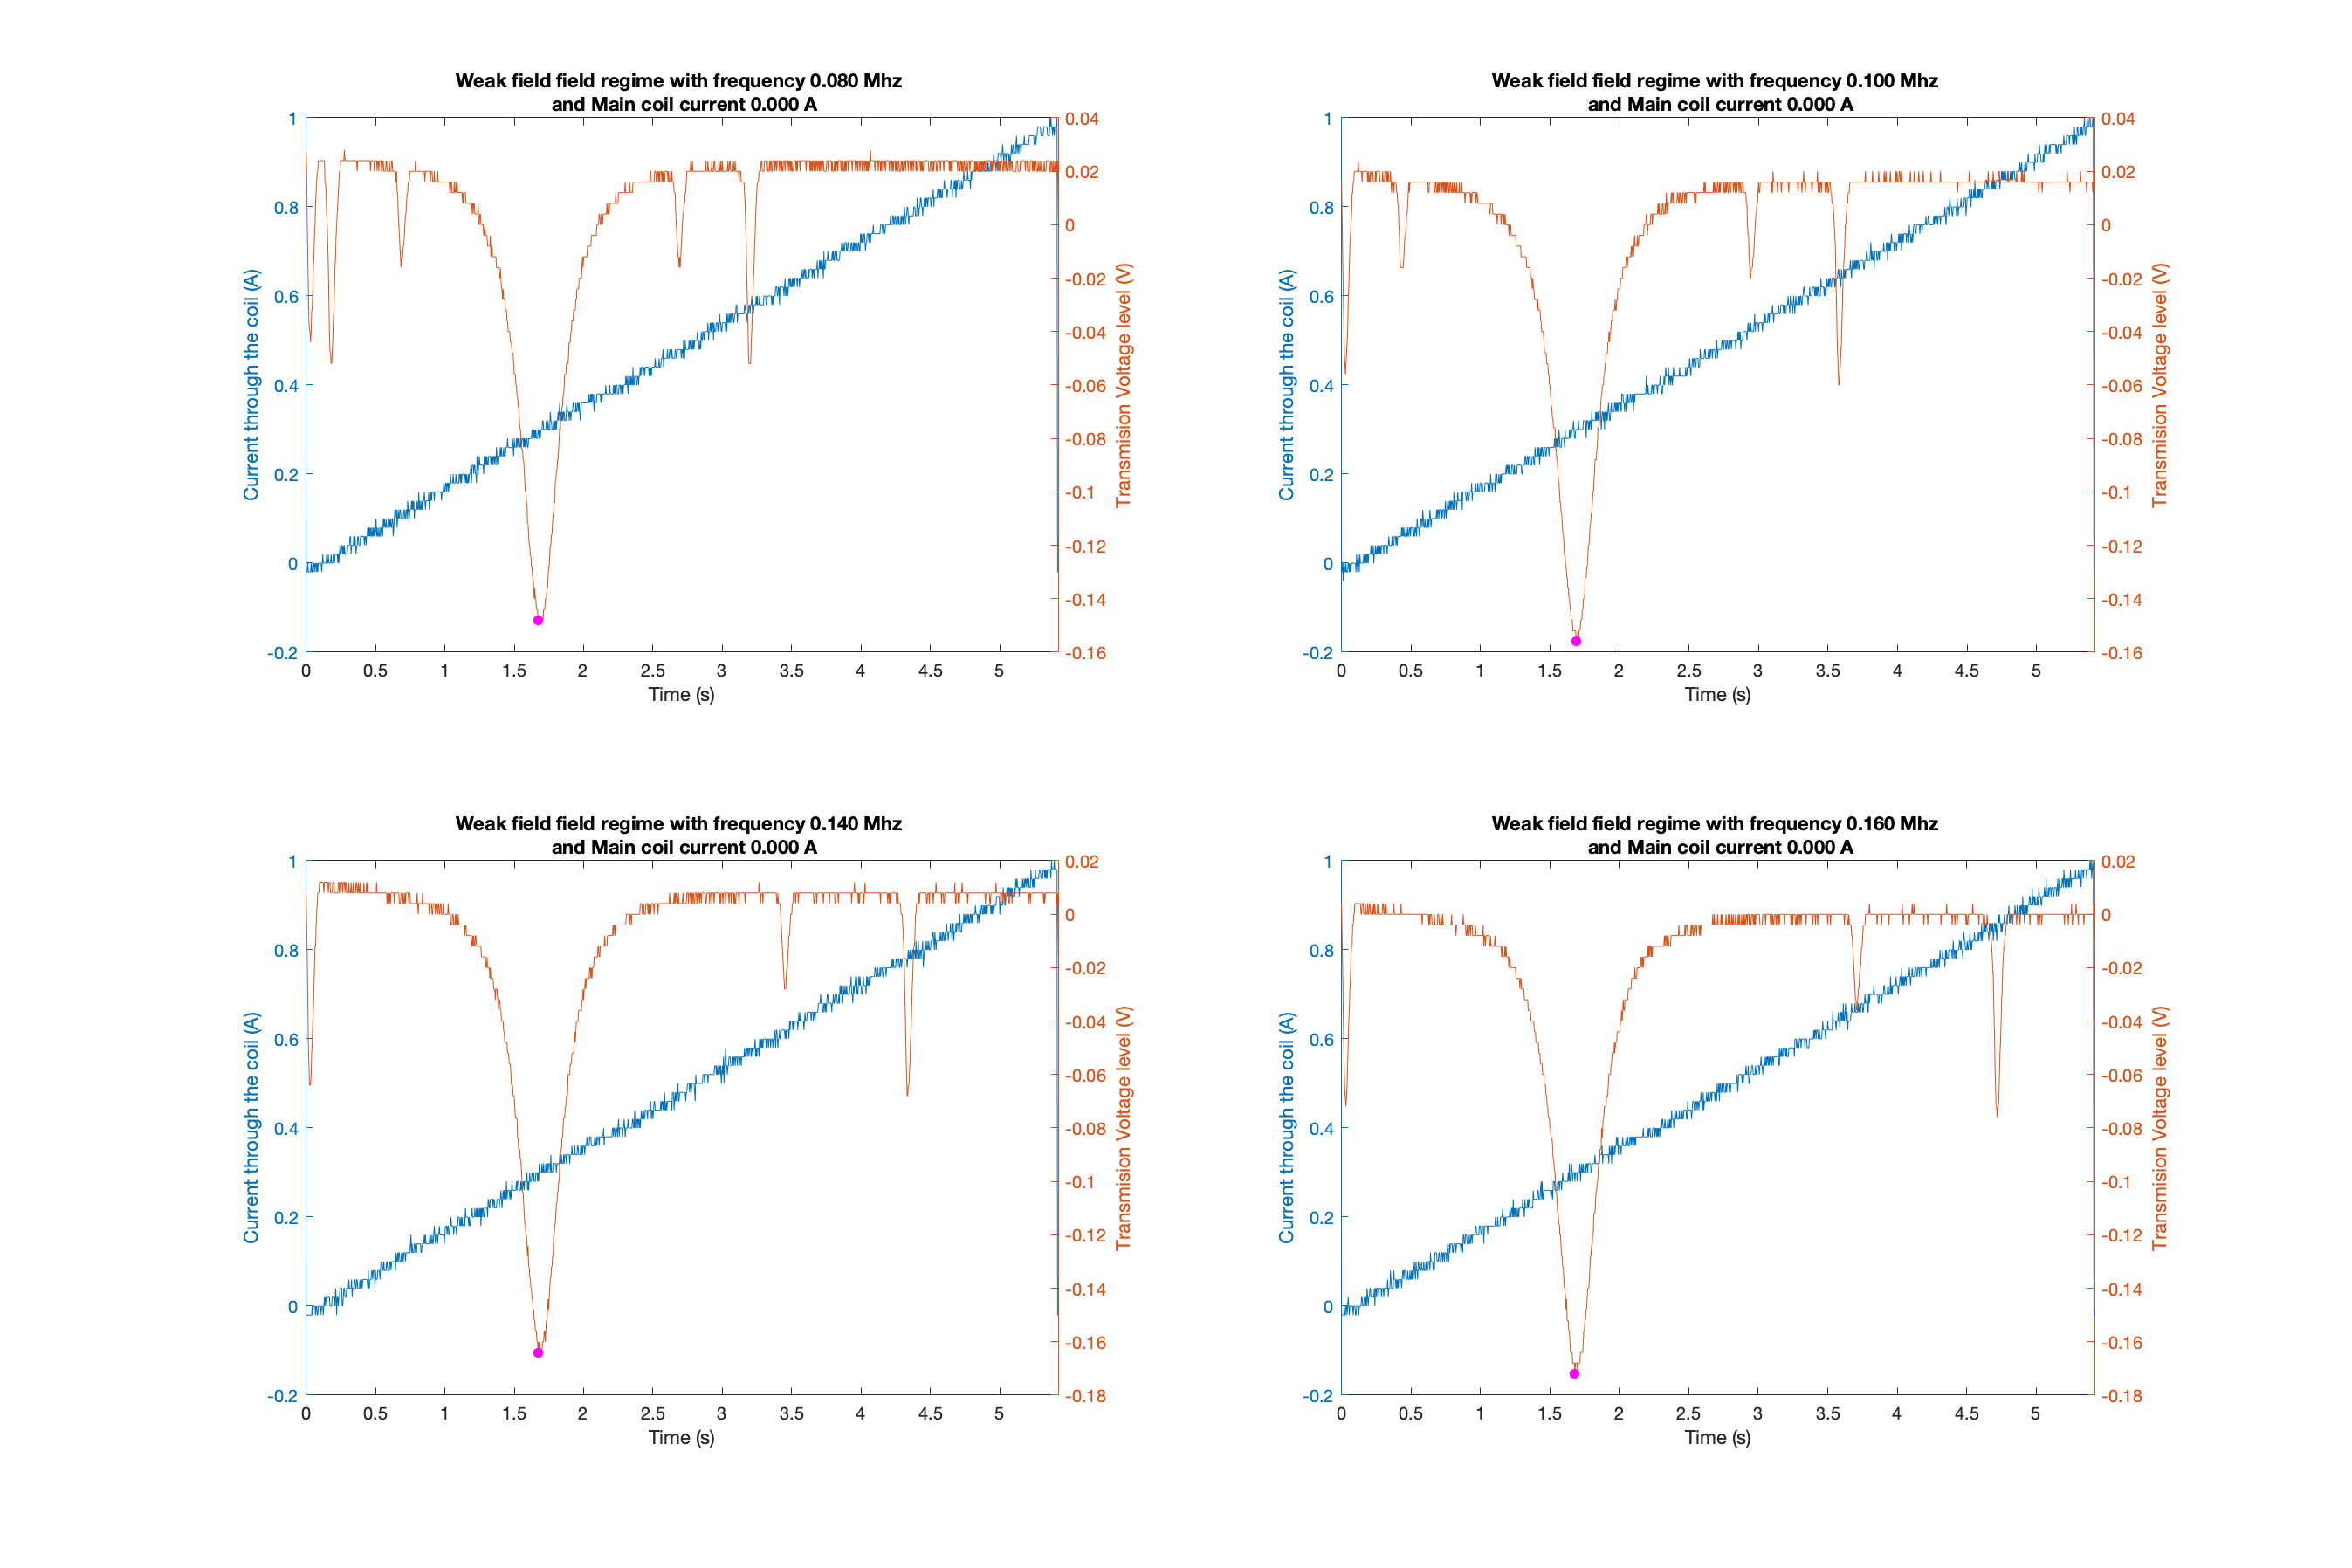

% - Determining ambient magletic field
% this can be done by taking the minimum reading of light transmission
% signal

[time_val_b0, current_val_b0, transmission_val_b0] = zero_field_peak(time, current, light_transmission);
% plot the peaks to check if they have been identified correctly
plot_current_transmission(rf_zero_bias, zeros(length(rf_zero_bias)), zero_bias_current_data, zero_bias_transmission_data, "Weak field", {time_val_b0', transmission_val_b0'});

Now, lets find the inverse peaks for both isotopes

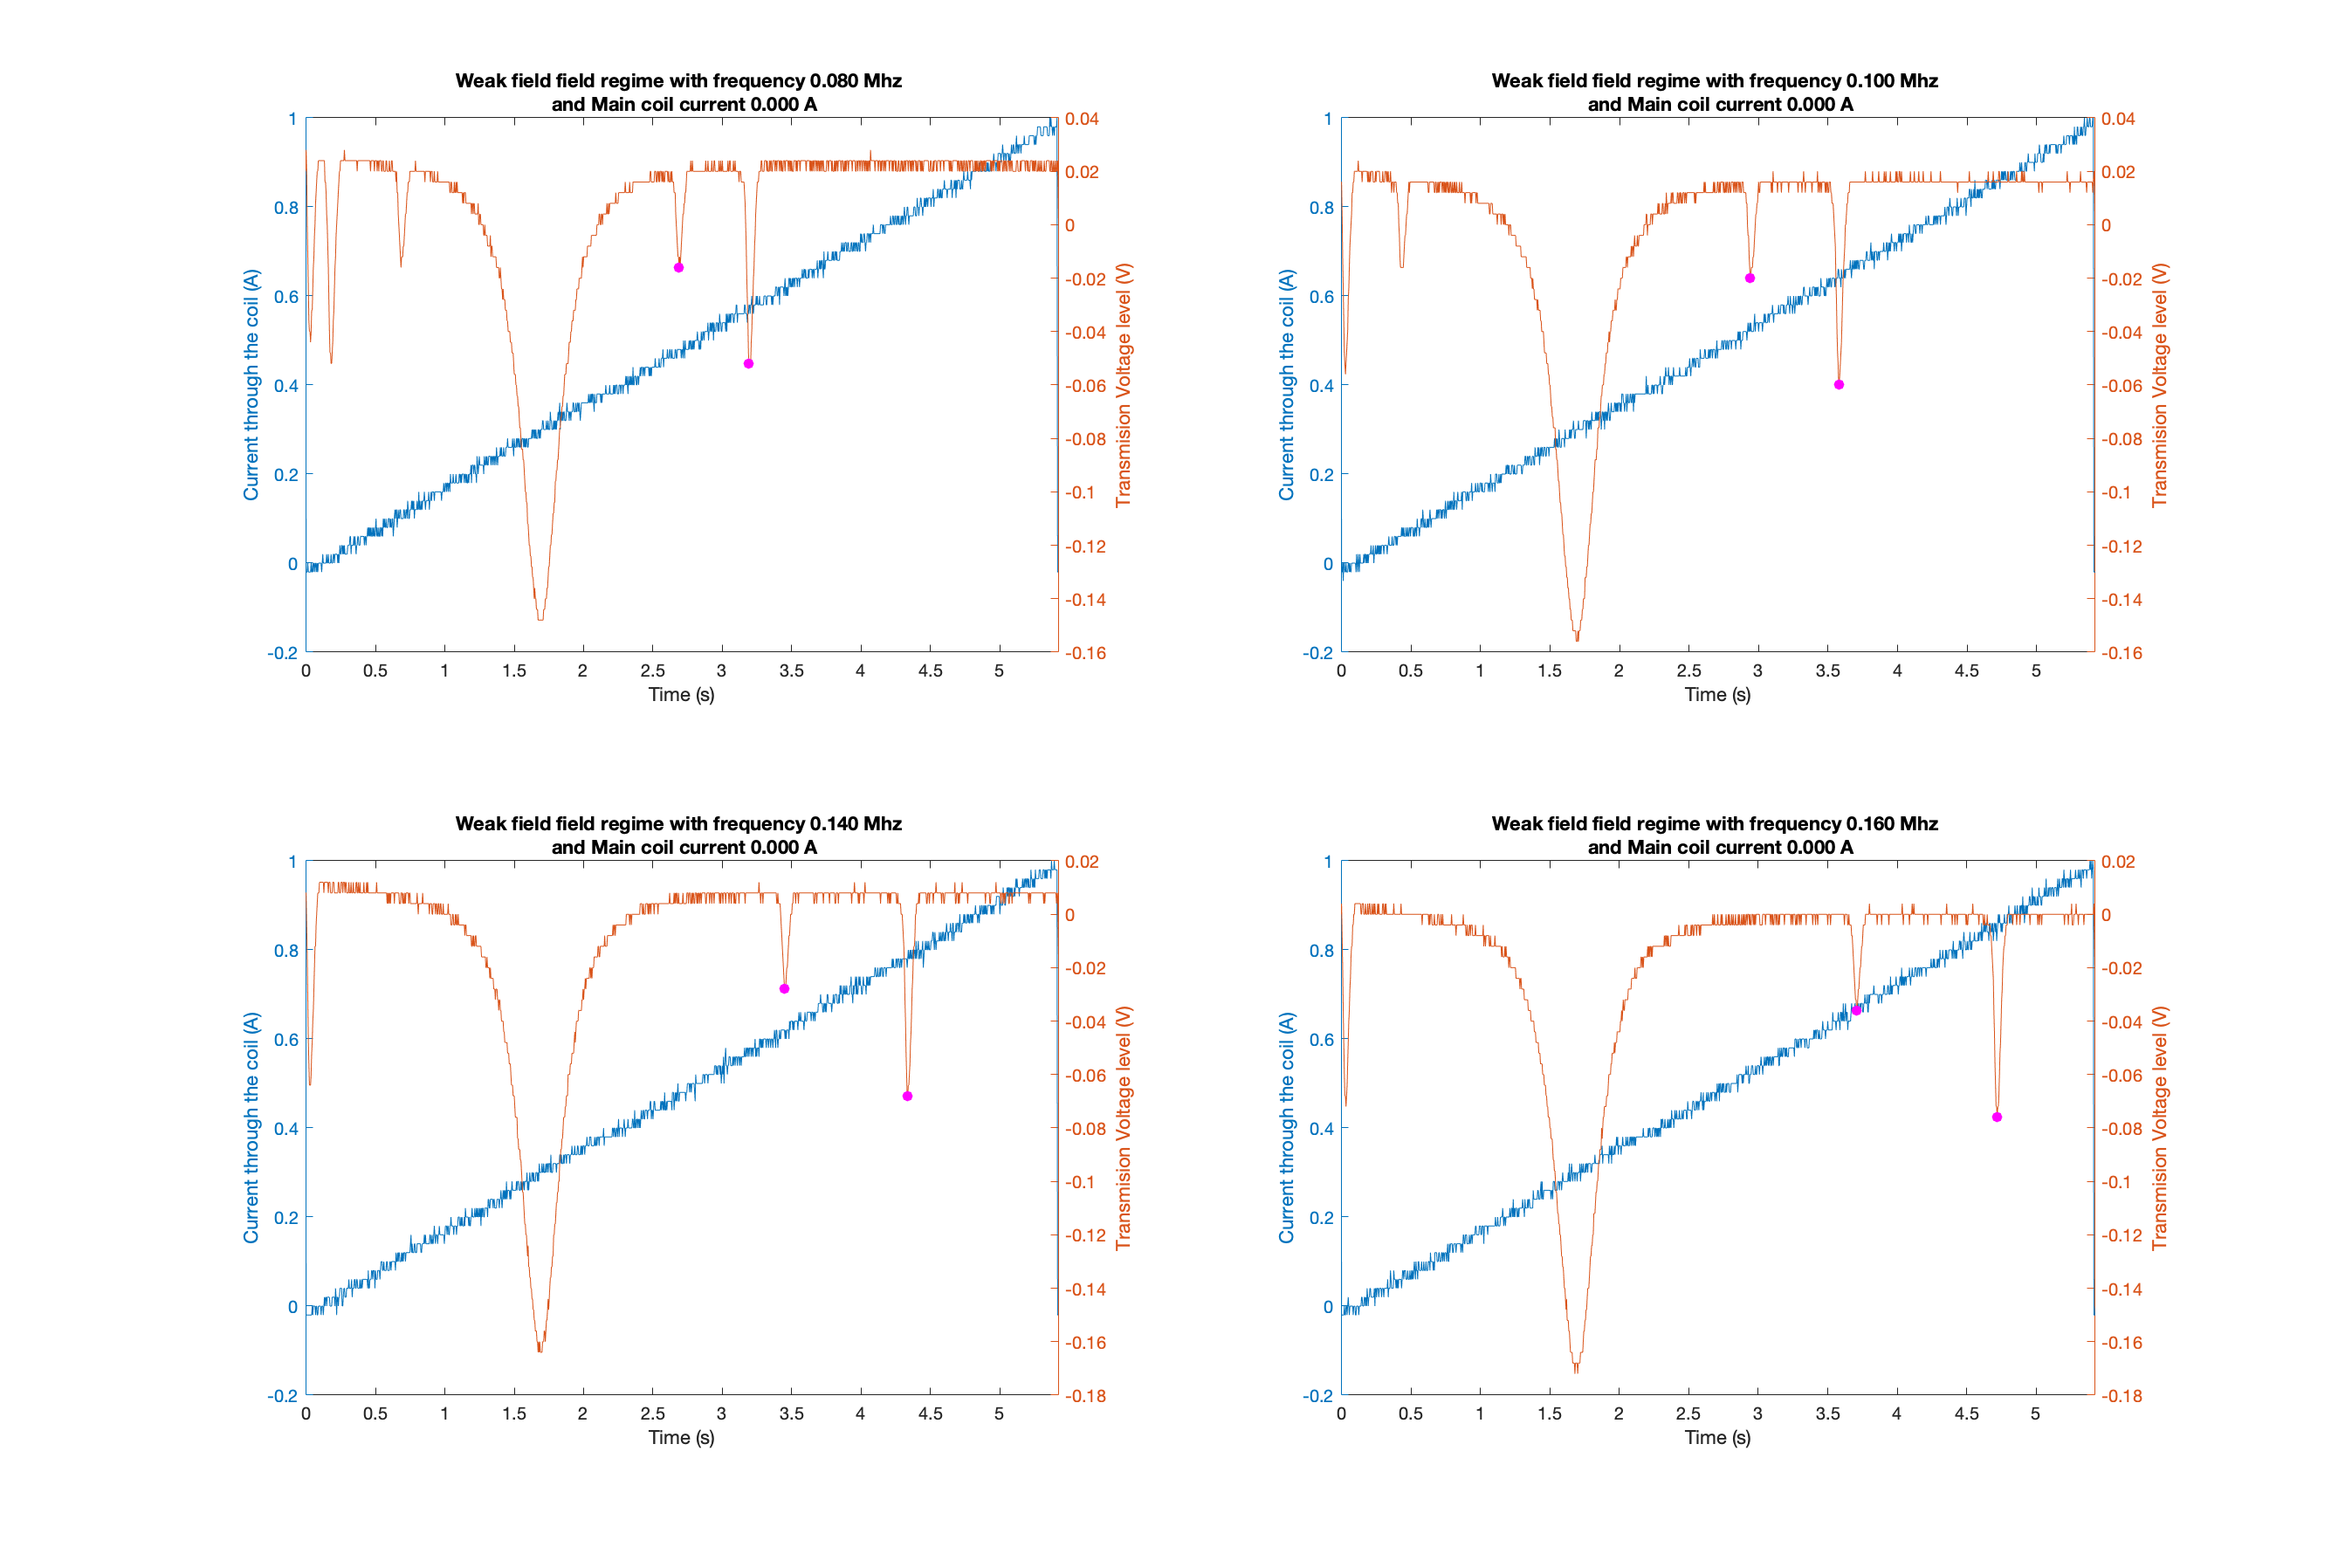

[time_val_iso, current_val_iso, transmission_val_iso] = find_iso_peaks(time, current, light_transmission, time_val_b0);
plot_current_transmission(rf_zero_bias, zeros(length(rf_zero_bias)), zero_bias_current_data, zero_bias_transmission_data, "Weak field", {time_val_iso, transmission_val_iso});

Now that we have current at inverse peak locations we plot **resonance RF vs current**.

Based on our previous graphs of magnetic field vs transition frequency, we know that Rb85 requires stroinger B field when comapred to Rb87 to experience transition at the same frequency, therefore we can figure out which peak corresponds to which isotope.

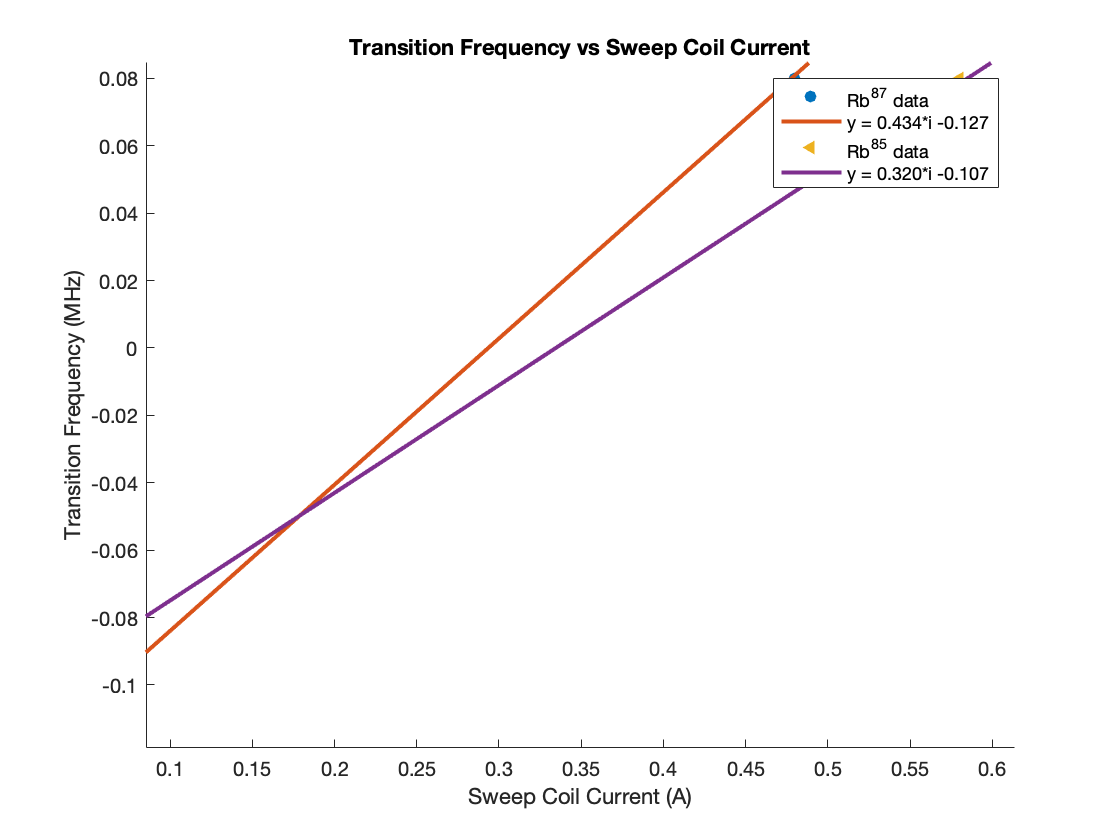

figure();
marker = ['o', '<'];
l =[];  % empty legend array
isotopes = ["Rb^{87} data", "Rb^{85} data"];
for index = 1:2
    x = current_val_iso(:,index);                                           % [A]
    x_fit = 0:0.01:max(x);
    y = frequency_weak_field(find(current_main_coil_weak == 0))/1000000;    % [Mhz]
    scatter(x, y,marker(index), "filled");
    l = [l, isotopes(index)];
    hold on
    % - Calculate linear fit
    [slope, intercept, linearfit] = linear_fit(x, y);
    l = [l, sprintf("y = %.3f*i %.3f",slope, intercept)];
    plot(x_fit, polyval(linearfit, x_fit), 'LineWidth',2);
    hold on
end
ylim([0, 0.20]);
xlim([0, 0.85]);
title("Transition Frequency vs Sweep Coil Current");
xlabel("Sweep Coil Current (A)");
ylabel("Transition Frequency (MHz)");
legend(l);

**Calibrating the magnettic field of sweep coil current **

We need an equation that is more precise than the ones derived from geometry of the coil set up: 


$$B_{sweep-ideal} = 8.991\times 10^{-3} (\frac{IN}{R})$$


where,


$$R = 0.16m\\\,
N = 11
$$


$B_{sweep-ideal} = 0.6181312\times I$ [G]

We can calculate the expected magnetic field values from the resonance equation:


$$\omega = g_F\mu_0B/h$$


Rearranging this equation we can solve for B:


$$B_{total} = \frac{\omega h}{g_F \mu_0}$$


where

$\omega - $transition frequency

$h -$ Planck's constant

$\mu_0 -$permiability of free spcace

And $B_{total} $ is the total magnetic field "felt" by the atoms, but we need $B_{sweep}$, so when we do our calculations we need to subtract $B_0$ current from the sweep current.

Once we plot this against current, we can determine the relationship between B field and the current:

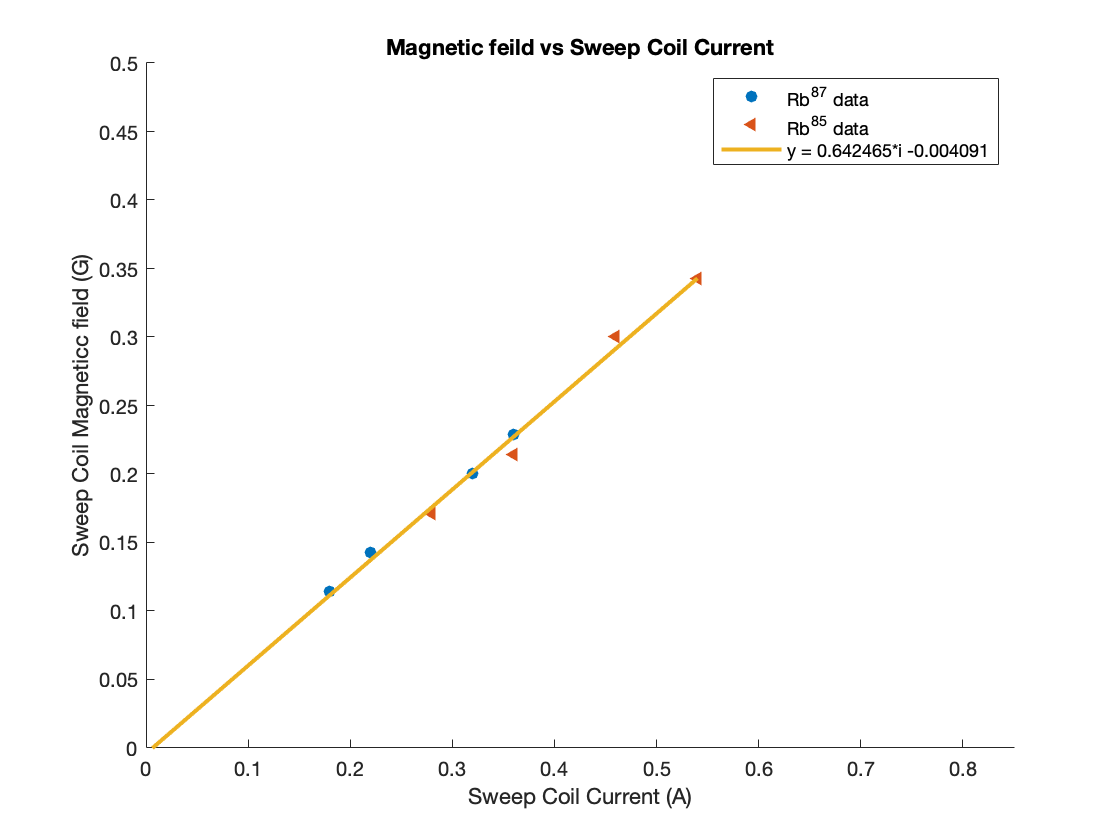

figure();
marker = ['o', '<'];
g_factors = [1/2, 1/3];
l =[];  % empty legend array
isotopes = ["Rb^{87} data", "Rb^{85} data"];
x_total = [];
y_total = [];
for index = 1:2
    % subtract the current at B_0 to determine field just due to sweep
    % coils
    x = current_val_iso(:,index) - current_val_b0(index);                                            % [A]
    x_total = [x_total, x'];
    y = (frequency_weak_field(find(current_main_coil_weak == 0))/(g_factors(index)*1.3996*10^6));    % [G]
    y_total = [y_total, y'];
    scatter(x, y,marker(index), "filled");
    l = [l, isotopes(index)];
    hold on
end

% - Calculate linear fit
x_fit = 0:0.01:max(x_total);
[slope, intercept, linearfit] = linear_fit(x_total, y_total);
l = [l, sprintf("y = %.6f*i %.6f",slope, intercept)];
plot(x_fit, polyval(linearfit, x_fit), 'LineWidth',2);
    
ylim([0, 0.50]);
xlim([0, 0.85]);
title("Magnetic feild vs Sweep Coil Current");
xlabel("Sweep Coil Current (A)");
ylabel("Sweep Coil Magneticc field (G)");
legend(l);

Fron now on we can use the following formula to calculate $B_{sweep}$

$B_{sweep-actual} = 0.642465*I-0..004091$ [Gauss]

$B_{sweep-predicted} = 0.6181312\times I$ [Gauss]

Conclusion:

- Actual and predicted are close to each other which tells us that were correct in our analysis

#### **Bias magnetic field in weak field regime**

Now, we can use additional data with non-zero bias field to determine the strength of the bias magnetic field as a function of current in the main coils.

We can calcuate bias magnetic by:


$$B_{main} = B_{total} - B_{sweep}$$


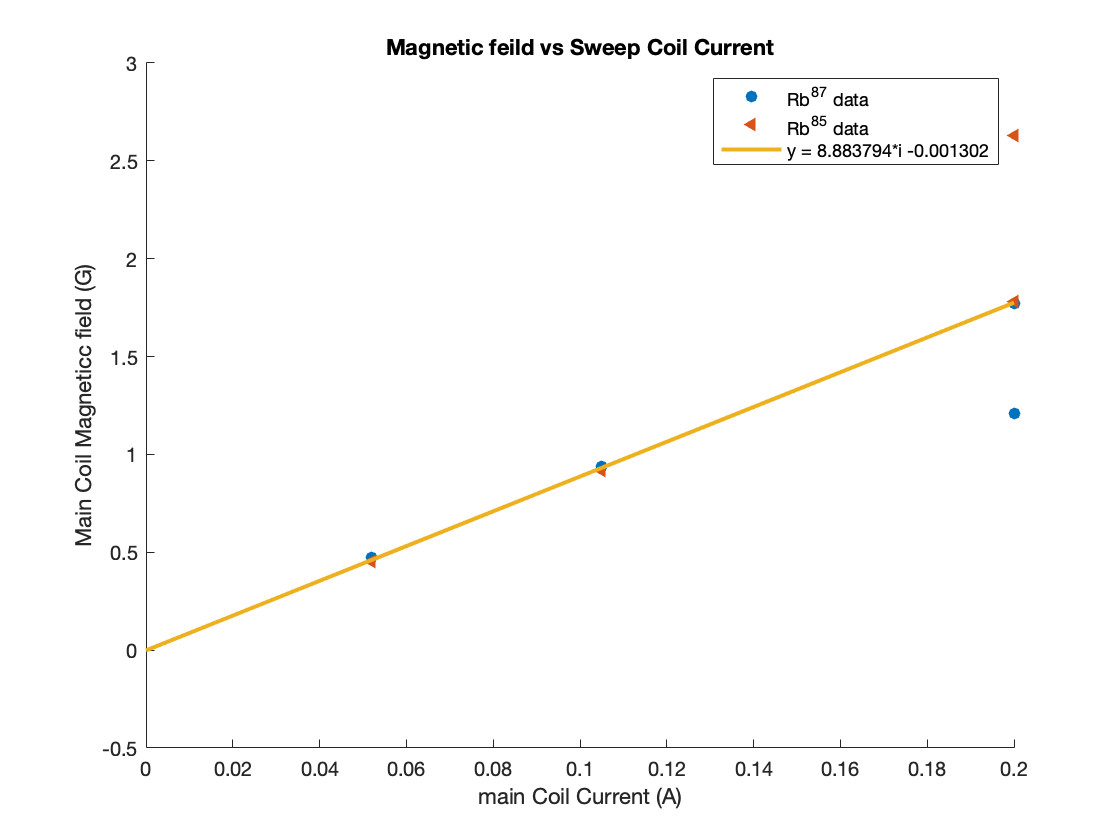

% - Get only data with non 0 bias current
bias_current_data = current_sweep_coil_weak(5:end,:,:);
bias_transmission_data = transmission_signal_data_weak(5:end,:,:);

% - Get timing data and voltage readings
time = bias_current_data(:,:,1);
current = bias_current_data(:,:,2);
light_transmission = bias_transmission_data(:,:,2);
rf_bias = frequency_weak_field(5:end);

% lets find peaks
[time_val_iso_bias, current_val_iso_bias, transmission_val_iso_bias] = find_iso_peaks(time, current, light_transmission, 0.9.*ones(length(rf_bias),1));
% plot_current_transmission(rf_bias, zeros(length(rf_bias)), bias_current_data, bias_transmission_data, "Weak field", {time_val_iso_bias, transmission_val_iso_bias});
magnetic_field_sweep = b_sweep(current_val_iso_bias);

figure();
marker = ['o', '<'];
g_factors = [1/2, 1/3];
l =[];  % empty legend array
isotopes = ["Rb^{87} data", "Rb^{85} data"];
x_total = [];
y_total = [];
for index = 1:2
    x = current_main_coil_weak(5:end);                                % [A]
    x_total = [x_total, x];
    magnetic_field_total = (rf_bias/(g_factors(index)*1.3996*10^6))'; % [G]
    magnetic_field_sw = magnetic_field_sweep(:,index);
    y = magnetic_field_total - magnetic_field_sw;                                
    y_total = [y_total, y'];
    scatter(x, y,marker(index), "filled");
    l = [l, isotopes(index)];
    hold on
end

% - Calculate linear fit
x_fit = 0:0.01:max(x_total);
x_total = [x_total(1:3), x_total(5:6), x_total(end)];
y_total = [y_total(1:3), y_total(5:6), y_total(end)];
[slope, intercept, linearfit] = linear_fit(x_total, y_total);
l = [l, sprintf("y = %.6f*i %.6f",slope, intercept)];
plot(x_fit, polyval(linearfit, x_fit), 'LineWidth',2);
    
% ylim([0, 0.50]);
% xlim([0, 0.85]);
title("Magnetic feild vs Sweep Coil Current");
xlabel("main Coil Current (A)");
ylabel("Main Coil Magneticc field (G)");
legend(l);

Then the formula to calculate magnetic field due to main coil is:

$B_{main} = 8.883794*i_{main}-0.001302$ (Gauss)

### **Calculating bias field in quadratic regime**

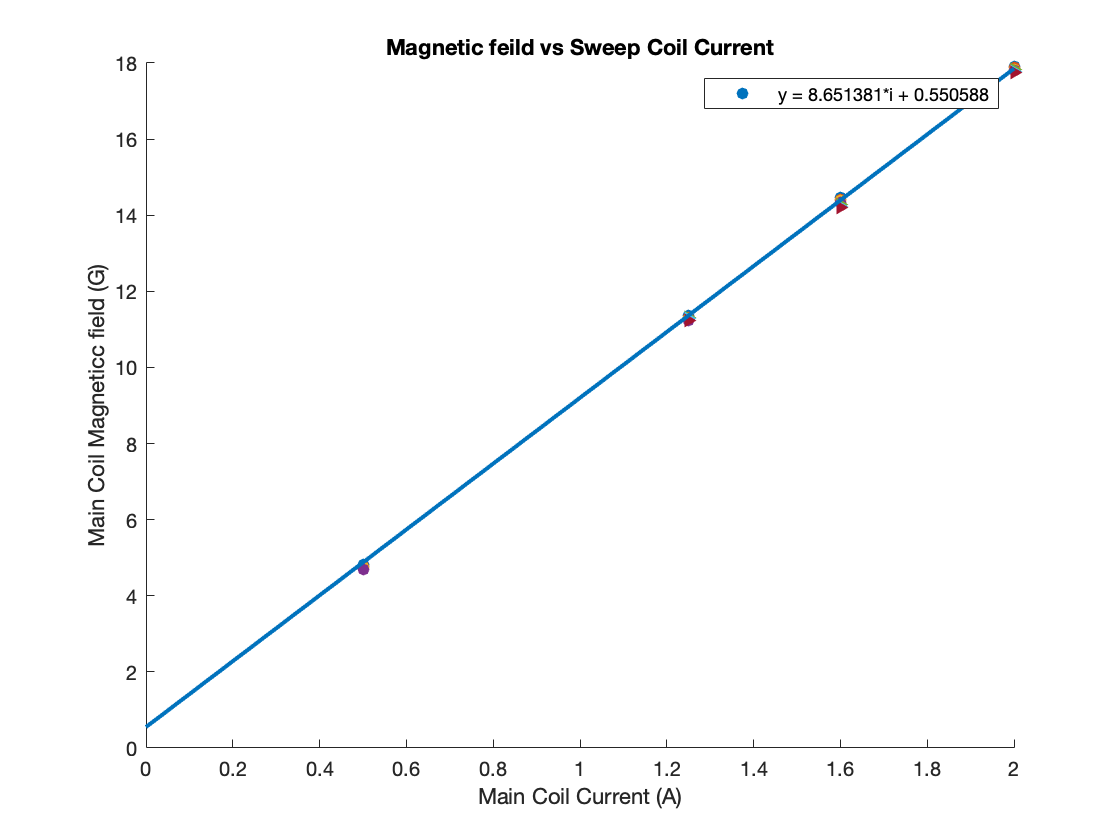

% - Get timing data and voltage readings
time = current_sweep_coil_quad(:,:,1);
current = current_sweep_coil_quad(:,:,2);
light_transmission = transmission_signal_data_quad(:,:,2);
% - Determining ambient magletic field
% this can be done by taking the minimum reading of light transmission
% signal

[time_val_quad, current_val_quad, transmission_val_quad] = find_iso_peaks_quad(time, current, light_transmission, 0.2*ones(length(frequency_quad_field),1));

% plot the peaks to check if they have been identified correctly
% plot_current_transmission(frequency_quad_field, zeros(length(rf_zero_bias)), current_sweep_coil_quad, transmission_signal_data_quad, "Strong field", {time_val_quad', transmission_val_quad'});
magnetic_field_sweep = [];
magnetic_field_sweep_87 = [];
f_85 = [];
i_85 = [];
f_87 = [];
i_87 = [];
% calculate magnetic sweep field from Rb85 peaks
for c = 1:length(frequency_quad_field)-1
    if length(current_val_quad{c}) == 6
        magnetic_field_sweep = [magnetic_field_sweep b_sweep(current_val_quad{c})];
        f_85 = [f_85, frequency_quad_field(c)];
        i_85 = [i_85, current_main_coil_quad(c)];
    else
        magnetic_field_sweep_87 = [magnetic_field_sweep_87 b_sweep(current_val_quad{c})];
        f_87 = [f_87, frequency_quad_field(c)];
        i_87 = [i_87, current_main_coil_quad(c)];
    end
end

figure();
marker = ['o','o','o','o','o','o','o','o'];
g_factors = 1/3*ones(length(i_85));
l =[];  % empty legend array
x_total = [];
y_total = [];
for index = 1:length(i_85)
    x = i_85;                                                   % [A]
    x_total = [x_total, x];
    magnetic_field_total = (f_85/(g_factors(index)*1.3996*10^6))'; % [G]
    magnetic_field_sw = magnetic_field_sweep(:,index);
    y = magnetic_field_total - magnetic_field_sw;                                
    y_total = [y_total, y'];
    scatter(x, y,marker(index), "filled");
    hold on
end

marker = ['>','>','>','>','>','>','>','>'];
g_factors_87 = 1/2*ones(length(i_87));
for index = 1:length(i_87)
    x = i_87;                                                   % [A]
    x_total = [x_total, x];
    magnetic_field_total = (f_87/(g_factors_87(index)*1.3996*10^6))'; % [G]
    magnetic_field_sw = magnetic_field_sweep(:,index);
    y = magnetic_field_total - magnetic_field_sw;                                
    y_total = [y_total, y'];
    scatter(x, y,marker(index), "filled");
    hold on
end

% - Calculate linear fit
x_fit = 0:0.01:max(x_total);
x_total = [x_total(1:3), x_total(5:6), x_total(end)];
y_total = [y_total(1:3), y_total(5:6), y_total(end)];
[slope, intercept, linearfit] = linear_fit(x_total, y_total);
l = [l, sprintf("y = %.6f*i + %.6f",slope, intercept)];
plot(x_fit, polyval(linearfit, x_fit), 'LineWidth',2);
    
% ylim([0, 0.50]);
% xlim([0, 0.85]);
title("Magnetic feild vs Sweep Coil Current");
xlabel("Main Coil Current (A)");
ylabel("Main Coil Magneticc field (G)");
legend(l);

The equation for the main coil current that we get from quadratic Zeemer effects is slightly different from the one that we got from linear Zeemer:

:  (Gauss)

$B_{main-linear} = 8.883794*i_{main}-0.001302$ (Gauss)

This is probably due to instability in peak finding algorithm.

### Task 3 v1

#### Goal: numerically model the change in population of electrons in ground state and the first excited state and **investigate whether the process of optical pumping is indeed re-distributing the ground state population towards the “dark” level.**

2 things to notes:

    1. We will only concern ourselves with $D_1
$transitions 

    2. We will only model the behaviour of $^{87}Rb$

Let $k$ lebel ground state ($^2{S_{1/2}}$) sub levels and $i$ label first excited state($^2P_{1/2}$) sublevels as follows:


$$|F, m_F\rangle \equiv |k\rangle\\\,
|1, -1\rangle \equiv |1\rangle\\\,
|1, 0\rangle \equiv |2\rangle\\\,
|1, 1\rangle \equiv |3\rangle\\\,
|2, -2\rangle \equiv |4\rangle\\\,
|2, -1\rangle \equiv |5\rangle\\\,
|2, 0\rangle \equiv |6\rangle\\\,
|2, 1\rangle \equiv |7\rangle\\\,
|2, 2\rangle \equiv |8\rangle
$$


Let $P_{ik}$ be the rate of stimulated transition and $\Gamma _{ik}$ be the rate of spontaneous decay, then we can define rate equations as follows


$$\dot{N}_k = \sum_iP_{ik}(N_i-N_k) +\sum_i\Gamma_{ik}N_i$$



$$\dot{N}_i = \sum_k P_{ik}(N_k-N_i) -\sum_k\Gamma_{ik}N_i$$


Where $N_i$ and $N_k$ are the population of electron in the first excited state and in ground state respectively


$${P_{ik} = \frac{6\pi c^2}{\hbar\omega_0^3}If_{ik}C_{ik}}$$


$I = c\epsilon_0E^2$ [W/m^2]


$$\Gamma_{ik}=\frac{1}{\tau}f_{ik}$$


% where f_ik and C_ik are defines as follows
global f_ik C_ik;
f_ik = [1/12 1/12 0 1/2 1/4 1/12 0 0;
        1/12 0 1/12 0 1/4 1/3 1/4 0;
        0 1/12 1/12 0 0 1/12 1/4 1/2;
        1/2 0 0 1/3 1/6 0 0 0;
        1/4 1/4 0 1/6 1/12 1/4 0 0;
        1/12 1/3 1/12 0 1/4 0 1/4 0;
        0 1/4 1/4 0 0 1/4 1/12 1/6;
        0 0 1/2 0 0 0 1/6 1/3];
C_ik = [0 1 0 0 0 1 0 0;
        0 0 1 0 0 0 1 0;
        0 0 0 0 0 0 0 1;
        1 0 0 0 1 0 0 0;
        0 1 0 0 0 1 0 0;
        0 0 1 0 0 0 1 0;
        0 0 0 0 0 0 0 1;
        0 0 0 0 0 0 0 0];
% - Define necessary constants
global tau omega_0 speed_of_light h_bar_si;
tau = 27.68*10^(-9);                 % lifetime in [s]
omega_0 = 2*pi*377.10746338*10^12;   % [Hz]
speed_of_light = 299792458;          % [m/s]
h_bar_si = 1.054571817*10^(-34);     % planks constant [m^2 kg / s]

% define differential equations
intensity = 30; % intensity of light [W/m^2]

% - Define initial conditions
N_k_0 = 1/8;
N_i_0 = 0;
x_init = [N_k_0*ones(1, 8), N_i_0*ones(1,8)];
interval = [0 2] * 10^(-6);

### Solving system of ODEs

% - Soilve system of ODES
[t, xa] = ode45(system_odes(intensity), interval, x_init);

### Plotting the results of the solution

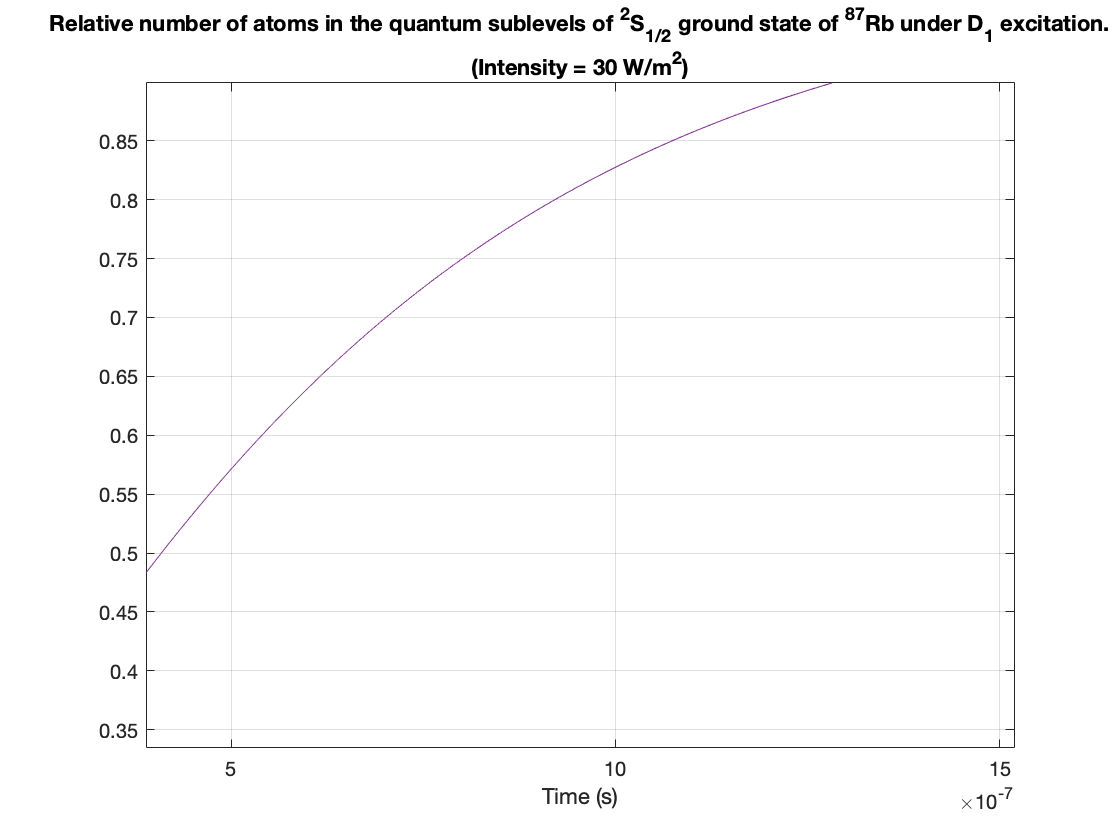

% - Plot the results of the solution
figure();
for index = 1:16
    x = t;
    y = xa(:,index)/sum(x_init);
    plot(x, y);
    hold on;
end
title(sprintf("Relative number of atoms in the quantum sublevels of ^2S_{1/2} ground state of ^{87}Rb under D_{1} excitation.\n(Intensity = %d W/m^2)", intensity));
xlabel("Time (s)")
ylim([0 1]);
grid on

**The absorption of the 87Rb gas as a function of time under continuous excitation by an external light source tuned to the frequency of D1 transition. **

**WARNING: this will take ~2min to run**

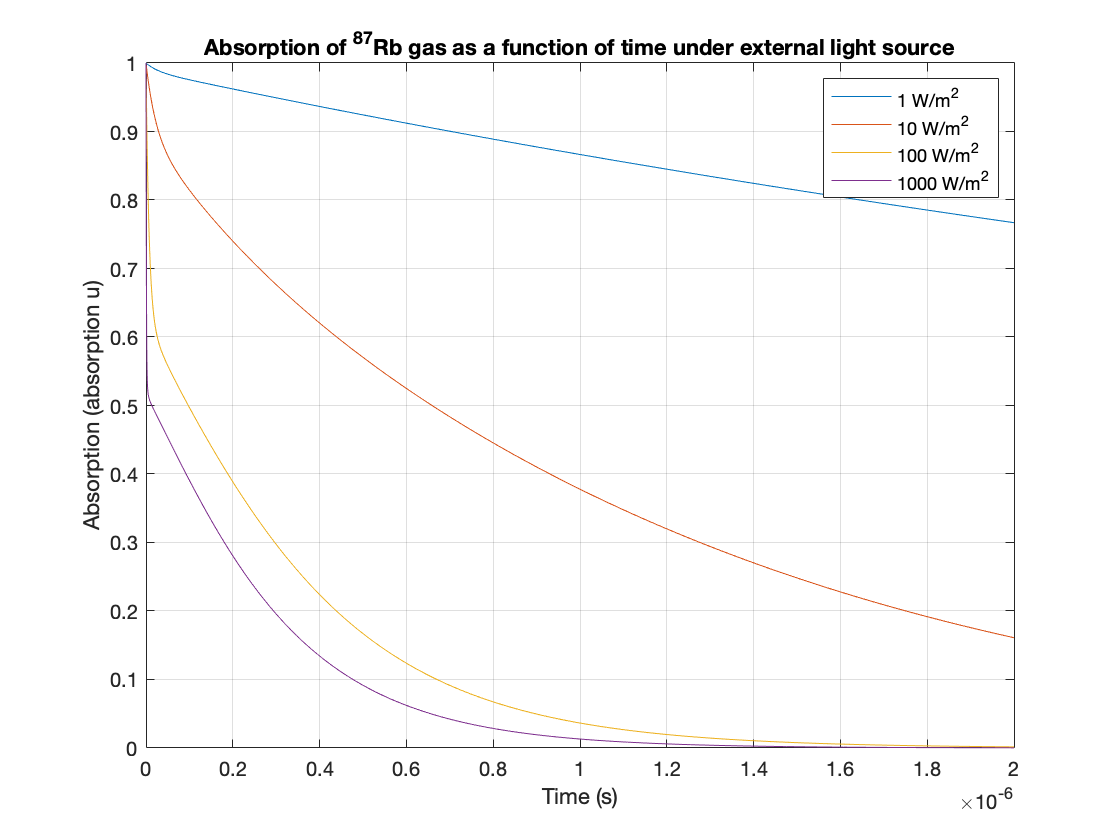

% - Calculating absorbtion for multiple intensities
intensities = [1, 10, 100, 1000];  % [W/m^2]
decay_rate = [];
figure();
l = [];
for intensity = intensities
    [t, xa] = ode45(system_odes(intensity), interval, x_init);
    abs = [];
    for k = 1:8
        col = xa(:,k);
        a = col*sum_transmision_rates(k,intensity);
        abs = [abs, a];
    end
    y = sum(abs, 2); % total population in the ground state
    y = y./max(y);   % scale in order to get absorption as a value between 0 and 1
    l = [l, sprintf("%d W/m^2", intensity)];
    plot(t, y);
    hold on;
end
title("Absorption of ^{87}Rb gas as a function of time under external light source")
xlabel("Time (s)");
ylabel("Absorption (absorption u)")
legend(l);
grid on

It is clear that the speed of absorption is proportional to the intensity of the external light. However it is not yet evident that we can increase intensity indefinitely to achieve virtually infinite absorption, lets explore higher intensities:

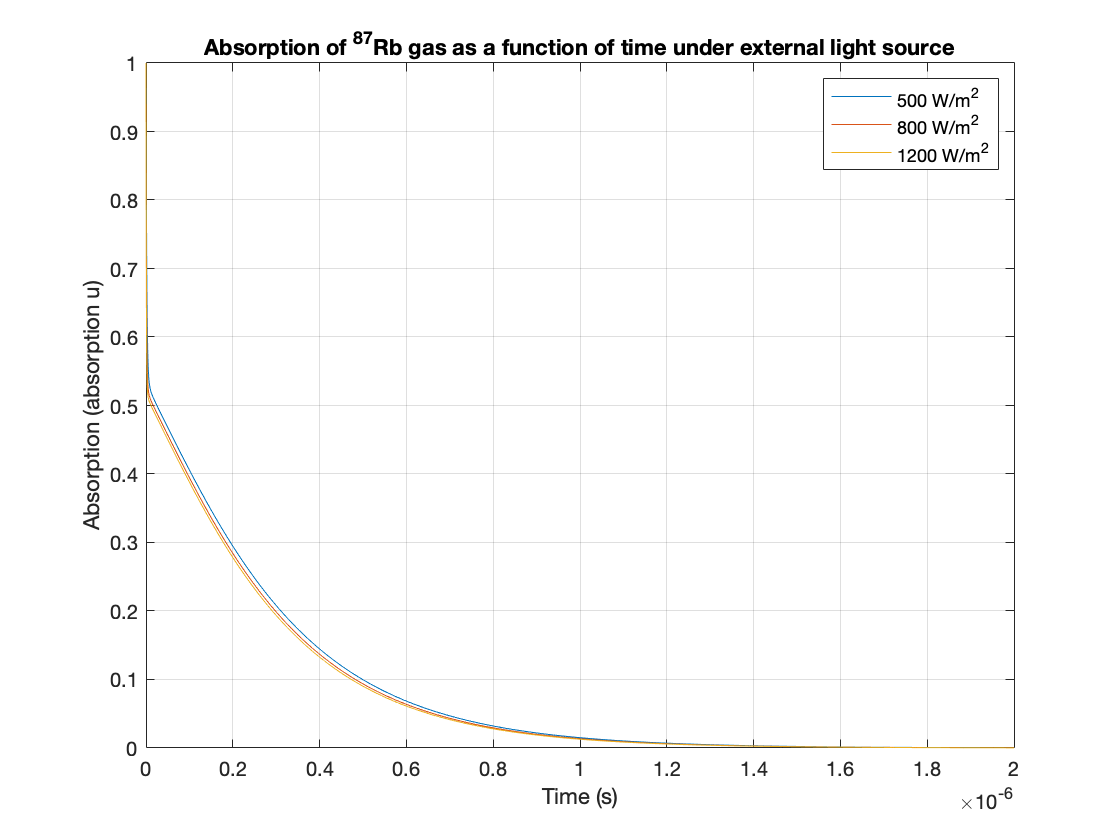

% - Calculating absorbtion for multiple intensities
intensities = [500, 800, 1200];  % [W/m^2]
summed_abs = [];
figure();
l = [];
for intensity = intensities
    [t, xa] = ode45(system_odes(intensity), interval, x_init);
    abs = [];
    for k = 1:8
        col = xa(:,k);
        a = col*sum_transmision_rates(k,intensity);
        abs = [abs, a];
    end
    y = sum(abs, 2); % total population in the ground state
    y = y./max(y);   % scale in order to get absorption as a value between 0 and 1
    l = [l, sprintf("%d W/m^2", intensity)];
    plot(t, y);
    hold on;
end
title("Absorption of ^{87}Rb gas as a function of time under external light source")
xlabel("Time (s)");
ylabel("Absorption (absorption u)")
legend(l);
grid on

From this graph it is clear that intensities beyond 800 W/m^2 dont significantly influence the absorption rate. This is probably due to spontaneous decay factor $\Gamma$ (specifically due to lifetime of the manifold -  $\tau$), **because this is the only factor in rate equations that decreases the population of excited state.**

We can run this again with $\tau$ that is smaller, and i think we will have a higher "speed limit"

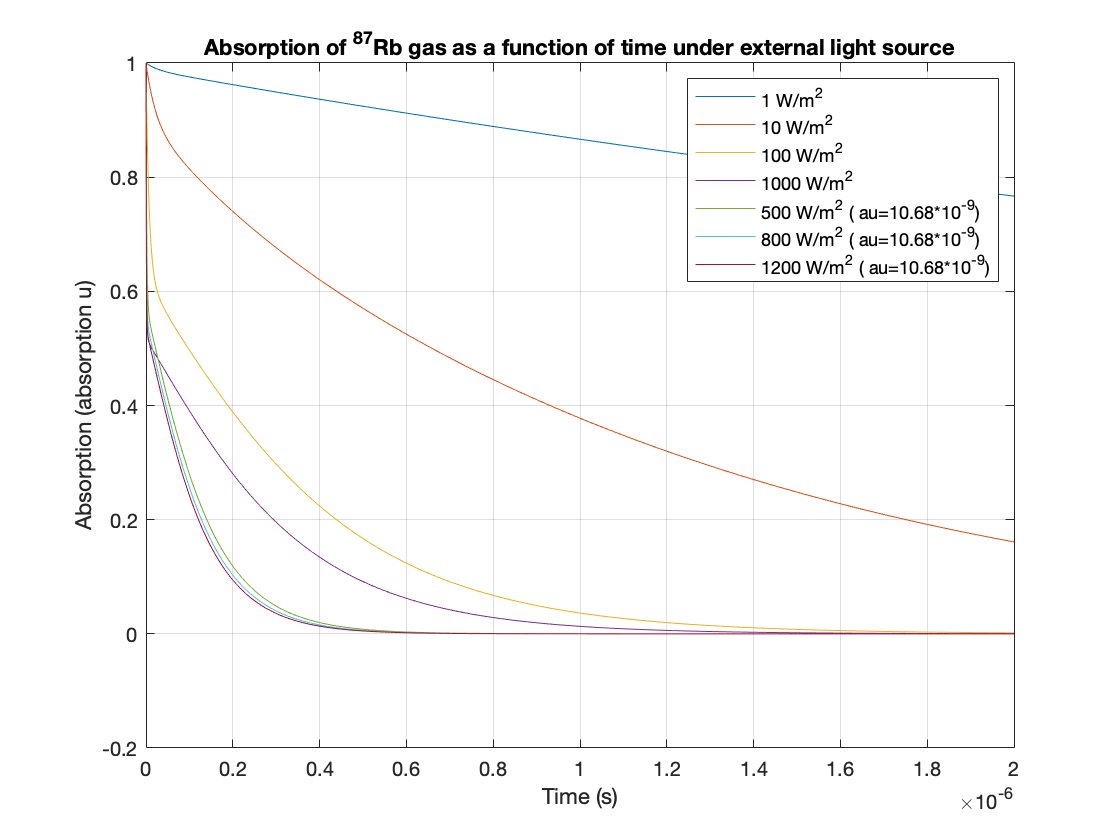

tau = 10.68*10^(-9);
% - Calculating absorbtion for multiple intensities
intensities = [500, 800, 1200];  % [W/m^2]
for intensity = intensities
    [t, xa] = ode45(system_odes(intensity), interval, x_init);
    abs = [];
    for k = 1:8
        col = xa(:,k);
        a = col*sum_transmision_rates(k,intensity);
        abs = [abs, a];
    end
    y = sum(abs, 2); % total population in the ground state
    y = y./max(y);   % scale in order to get absorption as a value between 0 and 1
    l = [l, sprintf("%d W/m^2 (\tau=10.68*10^{-9})", intensity)];
    plot(t, y);
    hold on;
end
title("Absorption of ^{87}Rb gas as a function of time under external light source");
xlabel("Time (s)");
ylabel("Absorption (absorption u)");
legend(l);
grid on

### Task 4

#### Goal: using numerical model from Task 3 determine the light intensity based in the decay curves

Import data from files first

% data importing and  file processing
data_folder = fullfile("OP3", "Transients");               % data directory relative to the script location
file_numbers =                [5, 9, 10];                      % these are the numbers of files that contain data

[pulse, transmission] = load_data(data_folder, file_numbers);
plot_decay(pulse, transmission);

In order compare the decay curves of our aquired data against our numerical models, we will first convert the experimental decay curves:

- Shit the beging of the decay curve 0 position

- Flip the decay curve vertically

- Scale the decay curve to have a maximum value of 1

% extract decay curves and shift them
[time, data] = extract_decay_curve(pulse, transmission);

Now that we have transformed the decay curve data, we will fit an exponenttial through noisy data to in order to have a function to compare to numerical models

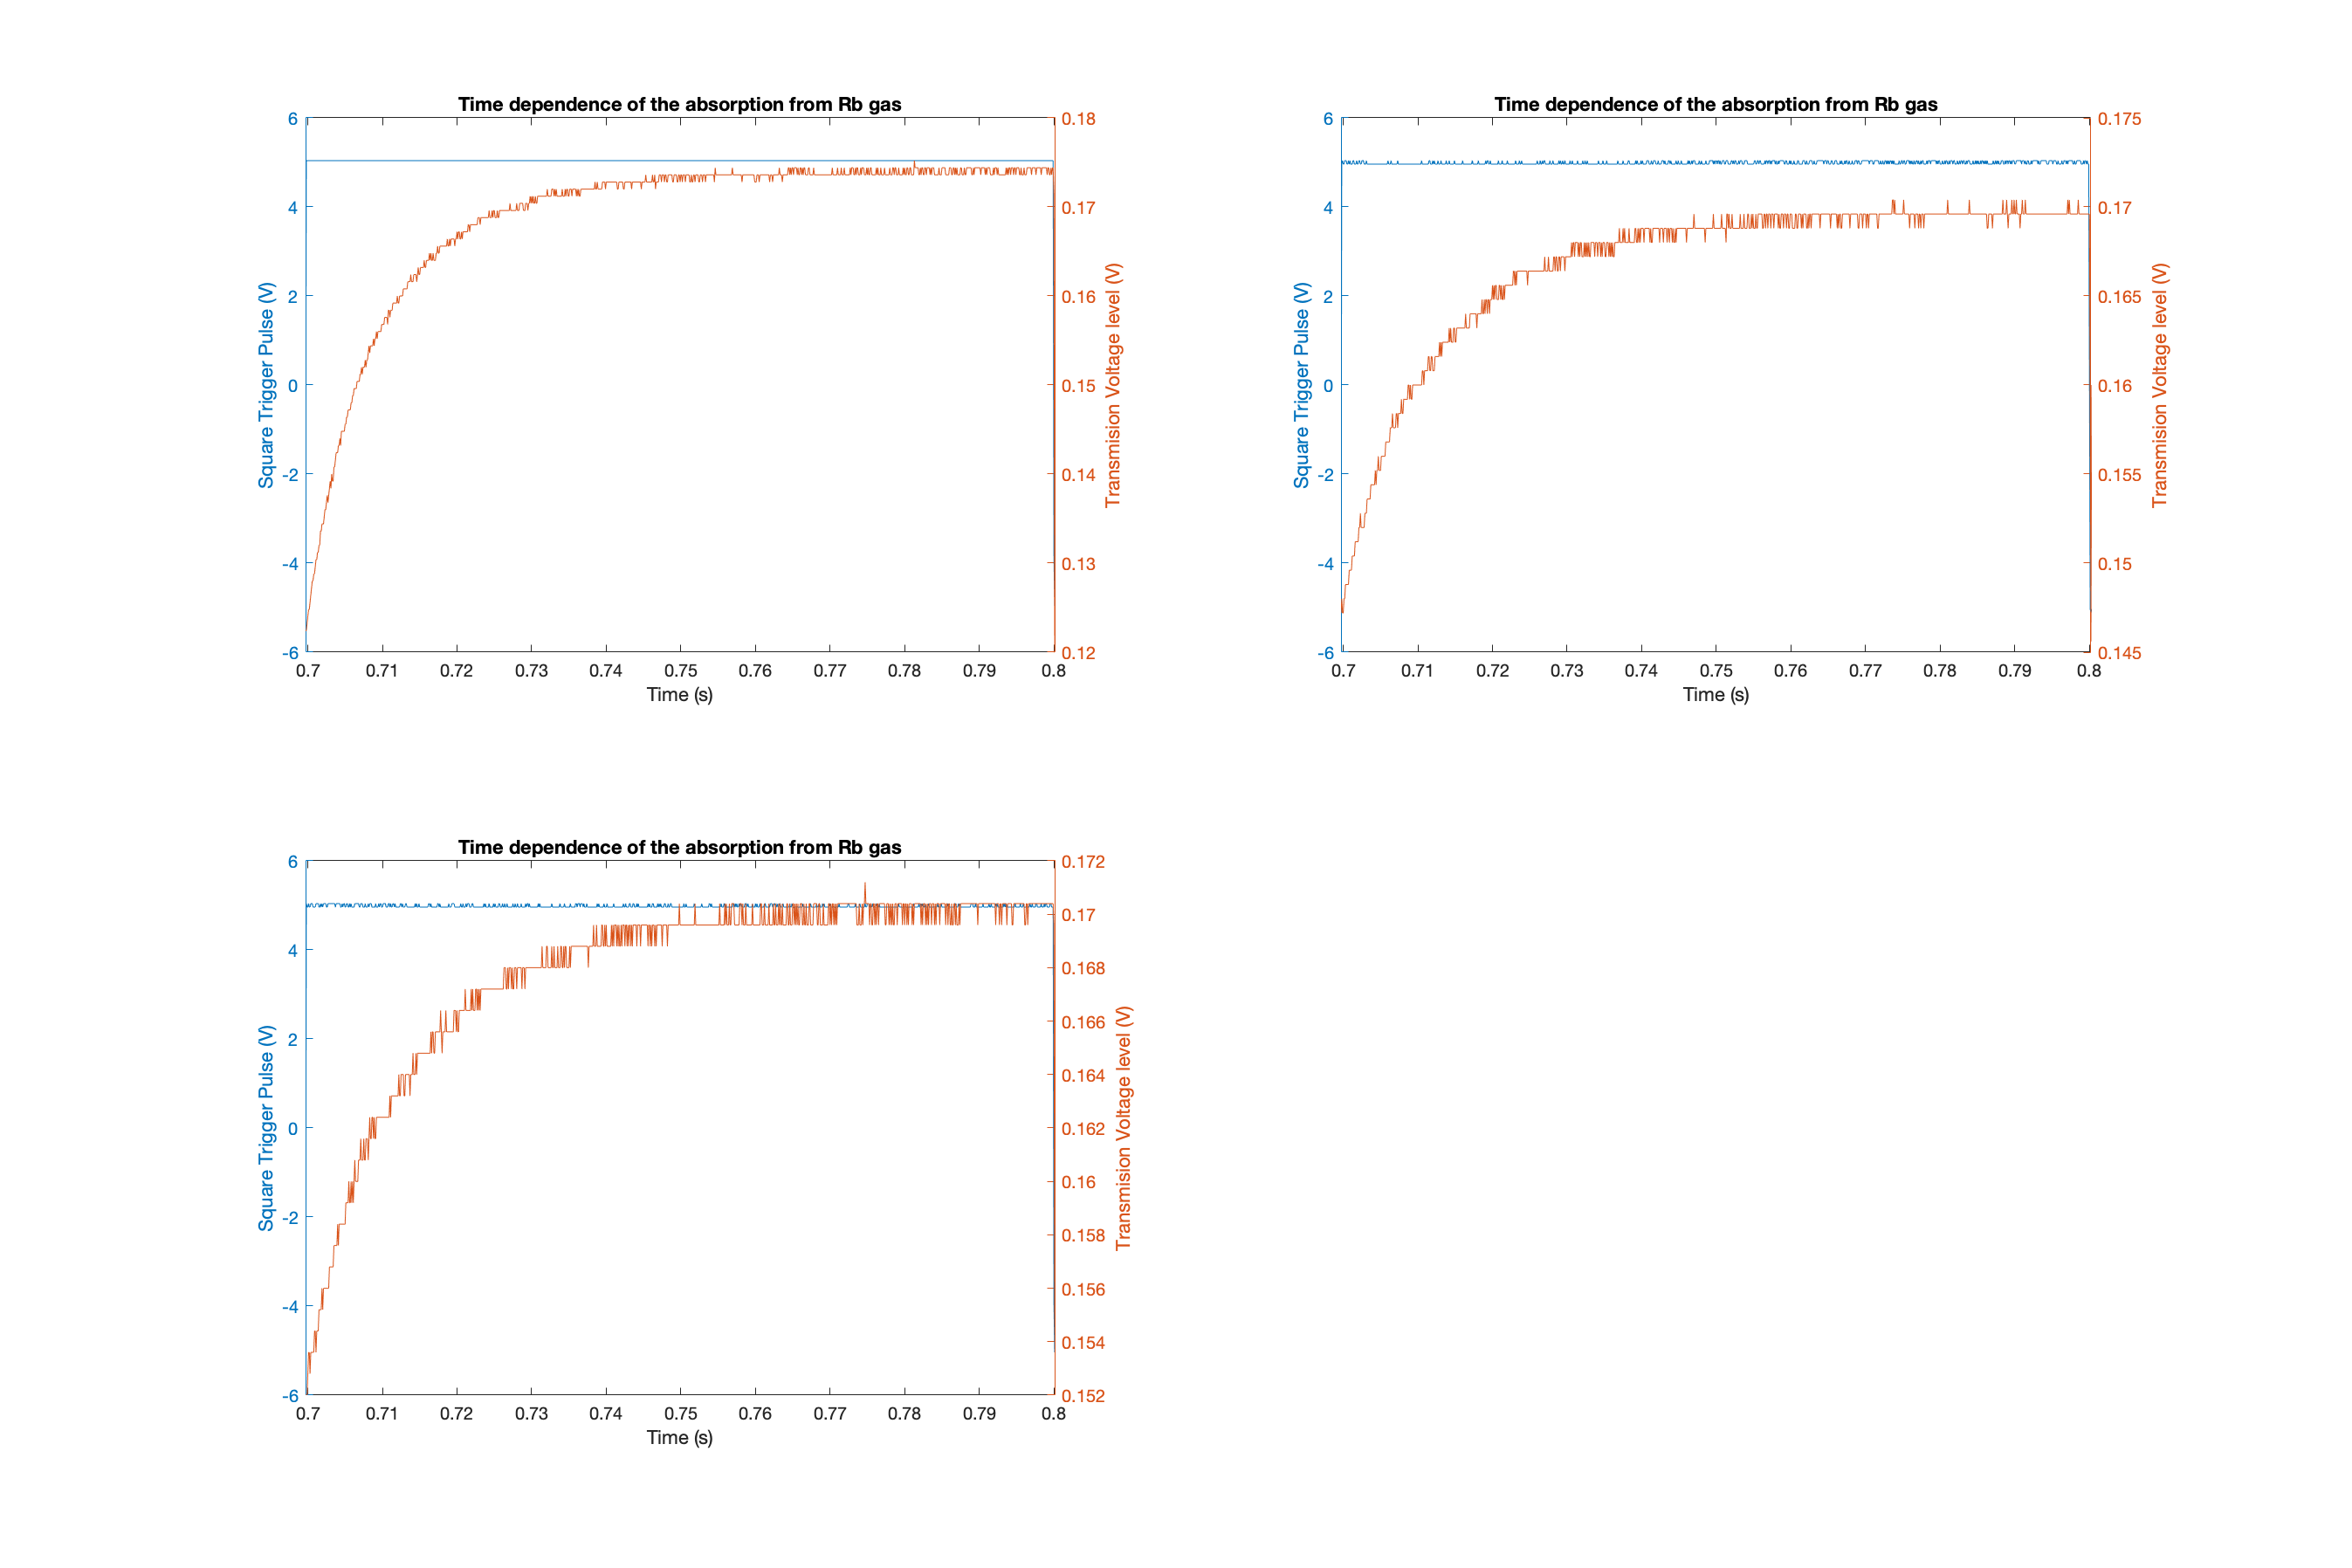

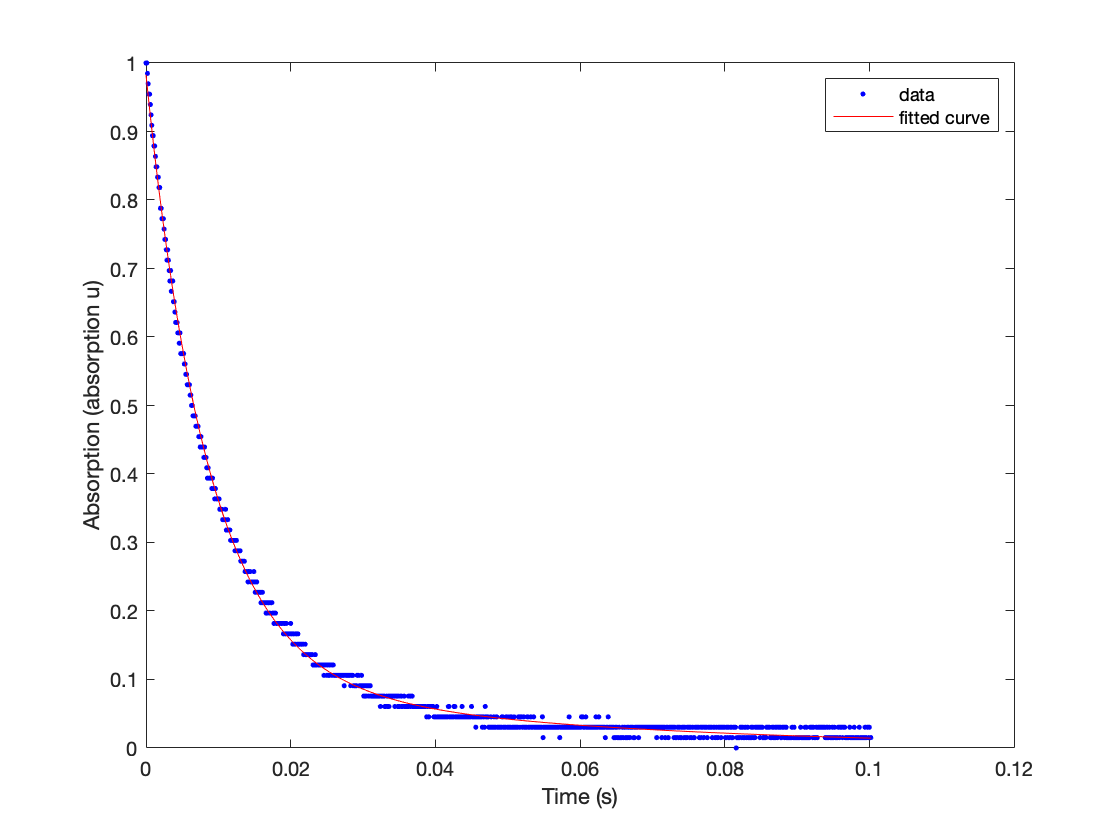

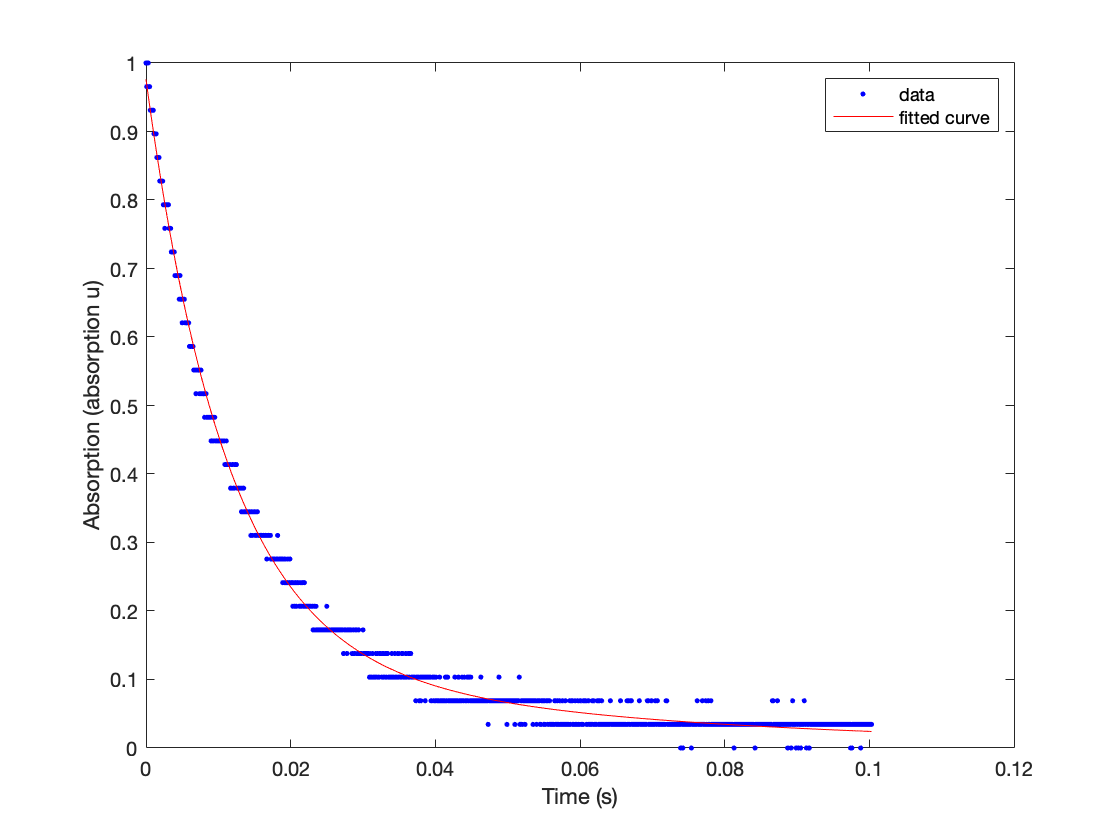

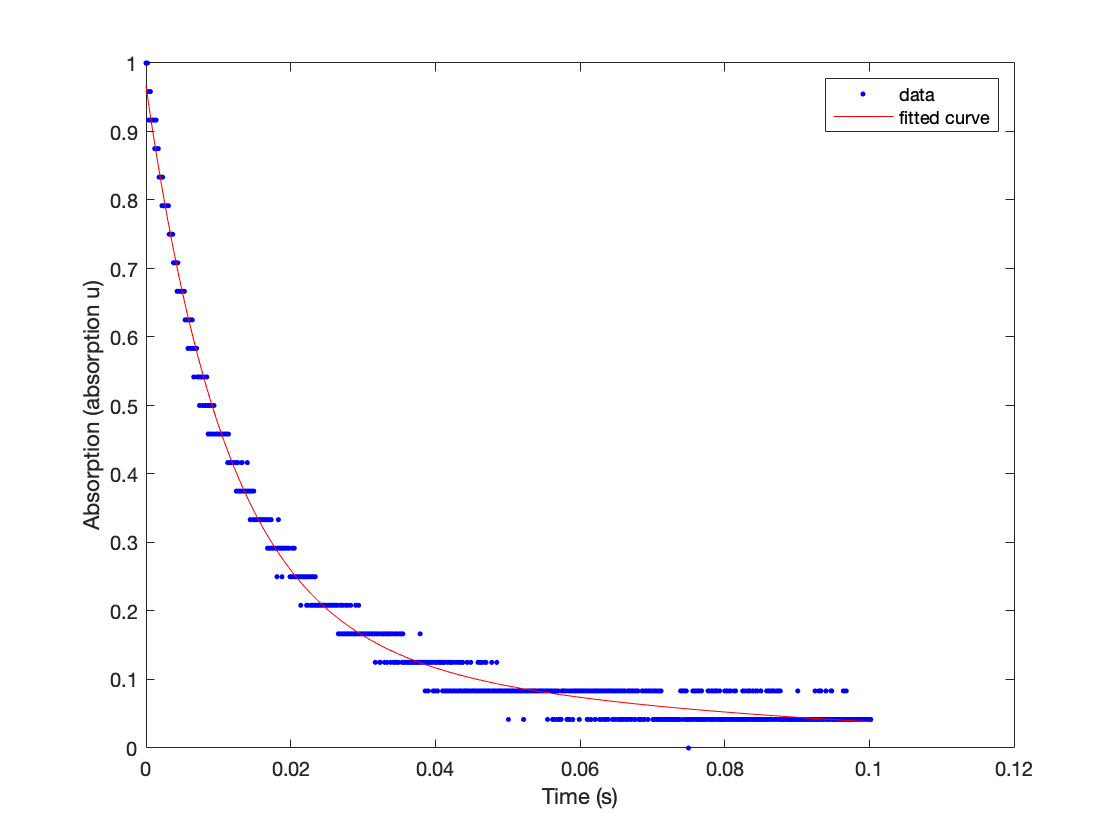

% - Plot decay curves to make sure they make sense
for index=1:size(data, 2)
    t = time{index};
    d = data{index};
    fitobj = fit(t', d', 'exp2');
    figure();
    plot(fitobj,t, d);
    xlabel("Time (s)");
    ylabel("Absorption (absorption u)");
end

## WARNING: This will take ~10min to run and generate data

In order to estimate the intensity of light for each one of these tests, I will first find a relationship between decay time of numerically computed curves,

that is, ill find the time at which absorption decreases by $1/e$ and i will plot it against intestity that was used to calculate numerical model.

interval = [0 2]*10^-4;   
intensities = 0.1:0.1:1;  % [W/m^2]
decay_rate = [];
for intensity = intensities
    [t, xa] = ode45(system_odes(intensity), interval, x_init);
    abs = [];
    for k = 1:8
        col = xa(:,k);
        a = col*sum_transmision_rates(k,intensity);
        abs = [abs, a];
    end
    y = sum(abs, 2); % total population in the ground state
    y = y./max(y);   % scale in order to get absorption as a value between 0 and 1
    decay_rate = [decay_rate, interp1(y,t,1/exp(1))];
end

Lets plot the data and check what the trend its like. And we can perform a fit to this data, that is aquiring a function that will calculate intensity given a time at $1/e$ of absoption.

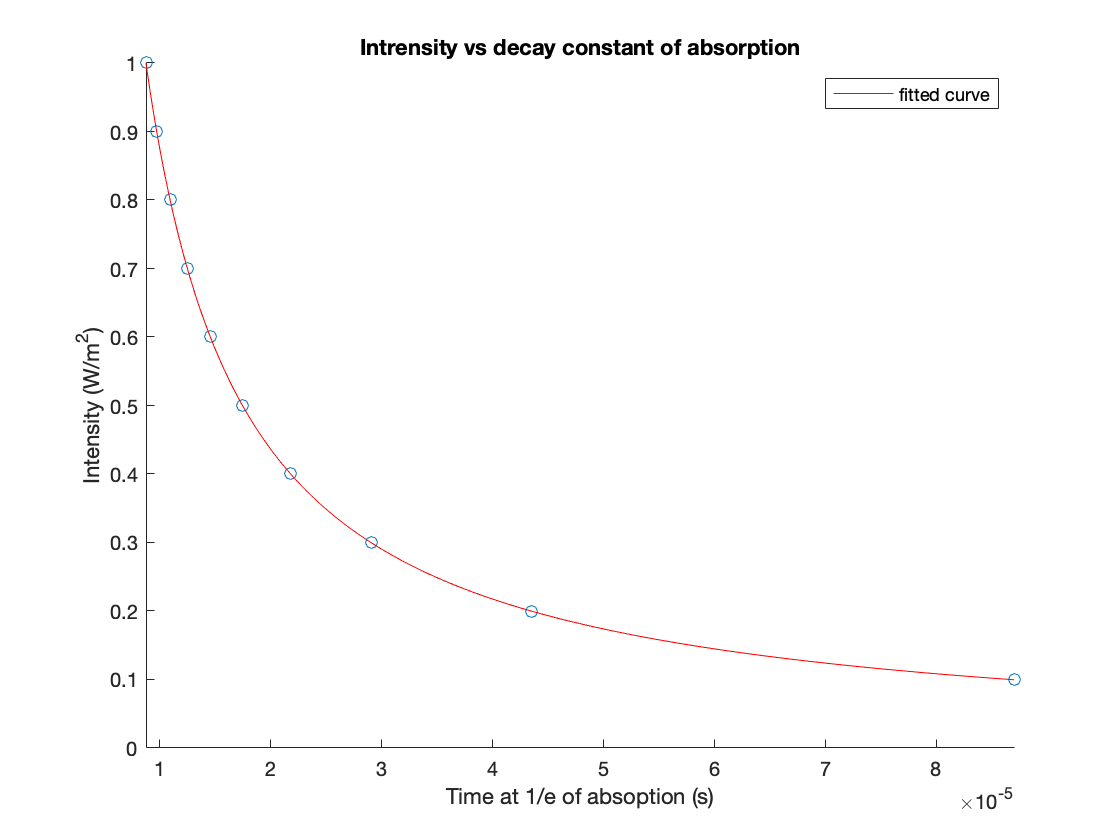

figure();
x = decay_rate;
y = intensities;

scatter(x, y);
ylim([0 max(y)]);
xlim([min(x) max(x)]);
hold on
intensity_decay_func = fit(x', y', 'power1');
plot(intensity_decay_func);
title("Intrensity vs decay constant of absorption")
xlabel("Time at 1/e of absoption (s)")
ylabel("Intensity (W/m^2)")

This provides us with a function to calculate the intensities:

$I = 8.313\times10^{-6} x^{-1.004}$ [$W/m^2$]

where $x$ is the time value at $1/e$ of absorption

I = [];
for index=1:size(data, 2)
    t = time{index};
    d = data{index};
    fitobj = fit(d', t', 'exp2');
    fitobj(1/exp(1));
    I(index) = intensity_decay_func(fitobj(1/exp(1)));
end

The predicted intensities are


$$I_{80} = 0.0098 W/m^2\\
I_{55} = 0.0115 W/m^2\\
I_{50} = 0.0124 W/m^2$$


### END

### Task 2 v1

Goal: For a given set of weak-field scans with zero bias field (no current in the main coils), determine the dependence of the resonance frequency νRF (known for each scan) on the indicated current in the sweep magnetic coils.

Step 1: Extract the data with 0 bias current

current_sweep_coil_weak;
transmission_signal_data_weak;
frequency_weak_field;
current_main_coil_weak;

% initialize variables to store data from the experiment with 0 bias fields
data_zero_bias_ch1 = [];
data_zero_bias_ch2 = [];
data_w_bias_ch1 = [];
data_w_bias_ch2 = [];

% save the required frequencies
freq_zero_bias = [];
freq_w_bias = [];
current_bias = [];
count = 1;
count_2 = 1;
% get subset of data with only 0 bias current
for index = 1:length(freq_weak)
    val = curr_weak{index};
    if val(2) == 0
        data_zero_bias_ch2(count,:,:) = transmission_signal_data_weak(index,:,:);
        data_zero_bias_ch1(count,:,:) = current_sweep_coil_weak(index,:,:);
        freq_zero_bias(count) = val(1);
        count = count + 1;
    else
        data_w_bias_ch2(count_2,:,:) = transmission_signal_data_weak(index,:,:);
        data_w_bias_ch1(count_2,:,:) = current_sweep_coil_weak(index,:,:);
        freq_w_bias(count_2) = val(1);
        current_bias(count_2) = val(2);
        count_2 = count_2 + 1;
    end
end

Task 2: Determining the dependance of resonance frequency $\nu_{RF}$ on the indicated current in the sweep magnetic coils

According to the OpticalPumping CalTech document we can calculate these frerquencies:


$$\nu_{RF} = g_F\mu_0B/h$$


We can calculate magnetic field B(Gauss):


$$B = 8.991\times 10^{-3} (\frac{IN}{R})$$


where,


$$R = 0.16m\\\,
N = 11
$$


Find largest inverse peak:

Fairly straighforward - the smallest value in channel 2 datasets should correspond to the largest inverse peak

[x, c, t] = zero_field_peak(data_zero_bias_ch1, data_zero_bias_ch2);

Lets find the dependence of resonance frequency on the the 

% get subset of data with only 0 bias current
peaks_n = [];
locs_n = [];
current_main_coil_weak = [];

for index = 1:length(freq_zero_bias)
%     try
%         clf(99+index);
%     catch ME
%     end
%     figure(99+index);
    [xmin,xmax] = find_min_max(data_zero_bias_ch1(index,:,2));
    data = data_zero_bias_ch2(index,:,2);
    [peaks, locs] = findpeaks(-data, 'MinPeakProminence',0.02, 'MinPeakDistance', 10);
    % remove peaks that are outside of range
    locs = locs(locs>xmin & locs<xmax);
    % filter out peacks that occure after B=0 peak
    
    time_of_peaks = data_zero_bias_ch2(index,locs,1);
    locs = locs(time_of_peaks >= x(index));
    locs_n(index, :) = locs;
    peaks = peaks(time_of_peaks >= x(index));
    peaks_n(index, :) = peaks;
    current_main_coil_weak(index, :) = data_zero_bias_ch1(index,locs,2);
%     hold on
%     plot(data_zero_bias_ch2(index,xmin:xmax,1), data(xmin:xmax));
%     hold on
%     scatter(data_zero_bias_ch2(index,locs,1), data_zero_bias_ch2(index,locs,2), 'or');
%     xlim([data_zero_bias_ch1(index,xmin,1) data_zero_bias_ch1(index,xmax,1)]);
end

figure();
l = [];
for c = 2:size(current_main_coil_weak, 2)
    y = freq_zero_bias;
    x = current_main_coil_weak(:, c)-current_main_coil_weak(:, 1);
    scatter(x, y,"blue","filled");
    l = [l, "Peak Data"];
    % fit line
    coefficients = polyfit(x, y, 1);
    xFit = linspace(min(x), max(x), 1000);
    yFit = polyval(coefficients , xFit);
    hold on;
    plot(xFit, yFit, 'LineWidth', 1);
    l(end+1)=sprintf("Slope = %.3f", (yFit(2)-yFit(1))/((xFit(2)-xFit(1))));
    hold on
    
end
legend(l);
title('Frequency vs Sweep Coil Current or ^{85}Rb and ^{87}Rb (with I_0 subtracted)')
ylabel('Frequency (KHz)');
xlabel('Current (A)');
ylim([min(freq_zero_bias) - 10 max(freq_zero_bias) + 10]);
xlim([0 0.6])


Calculating magnetic field at each current value

Now we can compare our experimentally determined magnitude of the B field vs the one predicted by the following equation:

$B = \frac{h\nu_{RF}}{g_f\mu_0}$,

where


$$
g_f = 1/3\text{ for }^{85}Rb\\\,
g_f = 1/2\text{ for }^{87}Rb\\\,
\frac{\mu_0}{h}=1.3996*10^{6} Hz/Gauss$$


b_field_85 = (1/(1.3996*10^6))*(freq_zero_bias*10^3)/(1/3);
b_field_87 = (1/(1.3996*10^6))*(freq_zero_bias*10^3)/(1/2);

b = b_field_85
figure();

x = (current_main_coil_weak(:, 3)-current_main_coil_weak(:, 1))';
y = b;
scatter(x, y,"blue","filled");


% fit line
coefficients = polyfit(x, y, 1);
xFit = linspace(0, max(x), 1000);
yFit = polyval(coefficients , xFit);
slope = (yFit(2)-yFit(1))/((xFit(2)-xFit(1)));
hold on
plot(xFit, yFit, 'LineWidth', 1);
hold on
    
title('Magnetic Field vs Sweep Coil Current or ^{85}Rb ' + sprintf("Slope = %.6f, Intercept = %.6f", slope, yFit(1)/slope))
ylabel('Magnetic field  (Gauss)');
xlabel('Sweep coil current (A)');
xlim([0 0.85]);
ylim([0 0.35])

b = b_field_87
figure();

x = (current_main_coil_weak(:, 2)-current_main_coil_weak(:, 1))';
y = b;
scatter(x, y,"blue","filled");


% fit line
coefficients = polyfit(x, y, 1);
xFit = linspace(0, max(x), 1000);
yFit = polyval(coefficients , xFit);
slope = (yFit(2)-yFit(1))/((xFit(2)-xFit(1)));
hold on
plot(xFit, yFit, 'LineWidth', 1);
hold on
    
title('Magnetic Field vs Sweep Coil Current or ^{87}Rb ' + sprintf("Slope = %.6f, Intercept = %.6f", slope, yFit(1)/slope))
ylabel('Magnetic field  (Gauss)');
xlabel('Sweep coil current (A)');
xlim([0 0.85]);
ylim([0 0.35])

We get an equation for B field:

$B_{85} = 0.638686*i_{sweep} - 0.012273$ (Gauss)

$B_{87} = 0.569315*i_{sweep} + 0.026200$ (Gauss)

% figure();
% x = b_field_experimental_85;
% y = b_field_85;
% scatter(x, y, "blue","filled");
% coefficients = polyfit(x, y, 1);
% xFit = linspace(min(x), max(x), 1000);
% yFit = polyval(coefficients , xFit);
% hold on
% slope_85 = (yFit(2)-yFit(1))/((xFit(2)-xFit(1)));
% Rsq1 = 1 - sum((y - slope_85.*x).^2)/sum((y - mean(y)).^2);
% plot(xFit, yFit, 'LineWidth', 1);
% title(sprintf('Experimentally determined B field vs predicted (^{85}Rb) with R^2=%.3f and slope = %.3f', Rsq1, slope_85))
% ylabel('Estimated by linear Zeeman magnetic field  (Gauss)');
% xlabel('Experimentally determined magnetic field  (Gauss)');
% xlim([0 0.36])
% ylim([0 0.36])
% 
% 
% figure();
% x = b_field_experimental_87;
% y = b_field_87;
% scatter(x, y, "blue","filled");
% coefficients = polyfit(x, y, 1);
% xFit = linspace(min(x), max(x), 1000);
% yFit = polyval(coefficients , xFit);
% hold on
% slope_87 = (yFit(2)-yFit(1))/((xFit(2)-xFit(1)));
% Rsq1 = 1 - sum((y - slope_87.*x).^2)/sum((y - mean(y)).^2);
% plot(xFit, yFit, 'LineWidth', 1);
% title(sprintf('Experimentally determined B field vs predicted (^{87}Rb) with R^2=%.3f and slope = %.3f', Rsq1, slope_87))
% ylabel('Estimated by linear Zeeman magnetic field  (Gauss)');
% xlabel('Experimentally determined magnetic field  (Gauss)');
% xlim([0 0.24])
% ylim([0 0.24])

Determining bias magnetic field as a function of of current in the main coil:


$$B_{bias} = B_{total} - B_{sweep}$$



$$B_{total} = \frac{h\nu_{RF}}{\mu_0g_f}$$


$B_{sweep} $ can be calculated using equations we got in porevious step

% get subset of data with only 0 bias current
peaks_85 = [];
peaks_87 = [];
locs_n = [];
current_main_coil_weak = [];

for index = 1:length(freq_w_bias)
%     figure();
    [xmin,xmax] = find_min_max(data_w_bias_ch1(index,:,2));
    data = data_w_bias_ch2(index,:,2);
    [peaks, locs] = findpeaks(-data, 'MinPeakProminence',0.02, 'MinPeakDistance', 10);
    % remove peaks that are outside of range
    locs = locs(locs>xmin & locs<xmax);
    % filter out peacks that occure after B=0 peak
    
    time_of_peaks = data_w_bias_ch2(index,locs,1);
    locs = locs(time_of_peaks >= x(index));
    locs_n(index, :) = locs;
    peaks = peaks(time_of_peaks >= x(index));
    if length(peaks) < 2
        peaks_85(index) = peaks(1);
    else
        peaks_85(index) = peaks(1);
        peaks_87(index) = peaks(2);
    end
    current_main_coil_weak(index, :) = data_w_bias_ch1(index,locs,2);
%     hold on
%     plot(data_w_bias_ch2(index,xmin:xmax,1), data(xmin:xmax));
%     hold on
%     scatter(data_w_bias_ch2(index,locs,1), data_w_bias_ch2(index,locs,2), 'or');
%     xlim([data_w_bias_ch1(index,xmin,1) data_w_bias_ch1(index,xmax,1)]);
end

% plot current vs magnetic field
figure();

b_field_85_bias_total = (1/(1.3996*10^6))*(freq_w_bias*10^3)/(1/3);
b_field_87_bias_total = (1/(1.3996*10^6))*(freq_w_bias(1:length(peaks_87))*10^3)/(1/2);

b_sweep_85 = 0.638686*peaks_85 - 0.012273;
b_sweep_87 = 0.569315*peaks_87 + 0.026200;

B_bias_85 = b_field_85_bias_total - b_sweep_85;
B_bias_87 = b_field_87_bias_total - b_sweep_87;

x = current_bias;
y = B_bias_85;
scatter(x, y,"blue","filled");


% fit line
coefficients = polyfit(x, y, 1);
xFit = linspace(0, max(x), 1000);
yFit = polyval(coefficients , xFit);
slope = (yFit(2)-yFit(1))/((xFit(2)-xFit(1)));
hold on
plot(xFit, yFit, 'LineWidth', 1);
hold on
    
title('Magnetic Field vs Main Coil Current or ^{85}Rb ' + sprintf("Slope = %.6f, Intercept = %.6f", slope, yFit(1)/slope))
ylabel('Magnetic field  (Gauss)');
xlabel('Main coil current (A)');

figure();
x = current_bias(1:length(peaks_87));
y = B_bias_87;
scatter(x, y,"blue","filled");

% fit line
coefficients = polyfit(x, y, 1);
xFit = linspace(0, max(x), 1000);
yFit = polyval(coefficients , xFit);
slope = (yFit(2)-yFit(1))/((xFit(2)-xFit(1)));
hold on
plot(xFit, yFit, 'LineWidth', 1);
hold on
    
title('Magnetic Field vs Sweep Coil Current or ^{87}Rb ' + sprintf("Slope = %.6f, Intercept = %.6f", slope, yFit(1)/slope))
ylabel('Magnetic field  (Gauss)');
xlabel('Sweep coil current (A)');

We get the following equations for the magnetic field bias:


$$B_{85} = 9.878611I_{main} + 0.015489\\\,
B_{87} = 8.174499I_{main} - 0.003877$$


Bias magnetic field in quadratic regime

### Task 4:

Import 'Calcukated transients data'

## Function definitions

Calculating $\hat{H}_B$ matrix for 

function mat = H_B_mat(B_0, total_nuc)
    global mu_b g_S g_I_87 g_I_85 s_e i_n_85 i_n_87;
    if total_nuc == 85
        I = i_n_85;
        g_I = g_I_85;
        s_i = [[1/2, 5/2]; [1/2, 3/2]; [1/2, 1/2]; [1/2, -1/2]; [1/2, -3/2]; [1/2, -5/2];...
              [-1/2,-5/2]; [-1/2, 5/2]; [-1/2, 3/2]; [-1/2, 1/2]; [-1/2, -1/2]; [-1/2, -3/2]]';
    elseif total_nuc == 87
        I = i_n_87;
        g_I = g_I_87;
        s_i = [[1/2, 3/2]; [1/2, 1/2]; [1/2, -1/2]; [1/2, -3/2]; [-1/2, -3/2]; [-1/2, 3/2]; [-1/2, 1/2]; [-1/2, -1/2]]';
    else
        print('ERROR: the atomic number is incorrect');
    end
    % calculate the size of the matrix
    n = (2*s_e+1)*(2*I+1);
    % create an identity matrix of the correct size
    % since the indecies of the kronecker delta in the H_b equation are the
    % same, the resulting matrix will be diagonal
    mat = mu_b*B_0*eye(n, n);
    
    index = 1;
    for val = s_i
        mat(index, index) = mat(index, index)*(g_S*val(1) + g_I*val(2));
        index = index + 1;
    end
end

function energy_delta = linear_zeemer(B, total_nuc)
    global mu_b;
    if total_nuc == 85
        F_mf_gf = [[2, 2, -1/3]; [2, 1, -1/3]; [2, 0, -1/3]; [2, -1, -1/3]; [2, -2, -1/3];...
                   [3, 3, 1/3];  [3, 2, 1/3];  [3, 1, 1/3];   [3, 0, 1/3]; [3, -1, 1/3]; [3, -2, 1/3]; [3, -3, 1/3]];
    elseif total_nuc == 87
        F_mf_gf = [[1, 1, -1/2]; [1, 0, -1/2]; [1, -1, -1/2]; [2, 2, 1/2];  [2, 1, 1/2];  [2, 0, 1/2]; [2, -1, 1/2]; [2, -2, 1/2]];
    else
        print('ERROR: the atomic number is incorrect');
    end
    % calculate the size of the matrix
    for index = 1:length(F_mf_gf)
        energy_delta(index) = mu_b*F_mf_gf(index, 3)*F_mf_gf(index, 2)*B;
    end
end

function ham = H_85(B_0)
    global H_hf_85;
    ham = H_B_mat(B_0, 85) + H_hf_85;
end

function ham = H_87(B_0)
    global H_hf_87;
    ham = H_B_mat(B_0, 87) + H_hf_87;
end

function f = file_name_ch1(val)
    f = "F00" + sprintf("%02d", val) + "CH1.CSV";
end

function f = file_name_ch2(val)
    f = "F00" + sprintf("%02d", val) + "CH2.CSV";
end

function plot_current_transmission(frequency_of_B, current_main_coil, current, transmission, regime, peaks)
    if nargin > 5
        peaks = peaks;
    else
        peaks = [];
    end
    l_freq = length(frequency_of_B);
    % determine subplot size based 
    subplot_size_x = ceil(sqrt(l_freq));
    figure1=figure('Position', [0 0 3000 2000]);
    for index = 1:length(frequency_of_B)
        subplot(subplot_size_x, subplot_size_x, index);
        
        f = frequency_of_B(index);                                % frequency of B field [Hz]
        c = current_main_coil(index);                             % main coil current [A]
        
        time = current(index,:,1);
        c_reading = current(index,:,2);
        yyaxis left; plot(time, c_reading);
        ylabel("Current through the coil (A)")
        
        time = transmission(index,:,1);
        t_reading = transmission(index,:,2);
        yyaxis right; plot(time, t_reading, "LineStyle","-");
        hold on;
        % plot peaks if there
        if ~isempty(peaks)
            try
                scatter(peaks{1}(index,:), peaks{2}(index,:), 'magenta', 'filled');
            catch ME
                scatter(peaks{1}{index}, peaks{2}{index}, 'magenta', 'filled');
            end
        end
        ylabel("Transmision Voltage level (V)")
        title(regime + sprintf(" field regime with frequency %.3f Mhz \n and Main coil current %.3f A", f/10^6, c));
        
        % since the data is periodic, we can get rid of 
        % any repeated data to make our analysis easier
        [xmin, xmax] = find_min_max(c_reading);
        % set the max value of x axis
        xlim([current(index,xmin,1) current(index,xmax,1)]);
        xlabel("Time (s)");
    end
end

function field = B_field(I)
    field = (8.991*10^(-3)) * 11 * I / 0.16;
end

function [time, current, transmission] = zero_field_peak(time_data, current_data, transmission_data)
    current = [];
    time = [];
    transmission = [];
    for index = 1:size(time_data,1)
        min_val = min(transmission_data(index,:));
        i = find(transmission_data(index, :) == min_val, 1);
        % get current at that value
        time(index) = time_data(index, i);
        current(index) = current_data(index,i);
        transmission(index) = min_val;
    end
end

function [amin, amax] = find_min_max(x)
    thresh = (max(x) - min(x))/3;
    amin  = nan;
    amax = nan;
    for i = 2:length(x)
        diff = abs(x(i-1) - x(i));
        if diff>thresh
            if isnan(amin)
                amin = i-1;
                
            else
                amax = i+1;
            end
        end
    end
end

function [c, t] = load_data(directory, numbers)
    current_filename = split(string(matlab.desktop.editor.getActiveFilename), filesep);      % determine the location of the livescript
    data_folder_location = fullfile(join(current_filename(1:end-1)',filesep), directory);          % remove the name of the script and assemble back
    
    for index = 1:length(numbers)
        number = numbers(index);
        sub_folder_name = "ALL00" + sprintf("%02d", number) + " copy";
        % get channel 1 data - voltage applied to sweep coils,but since the
        % resistance is 1 Ohm it is aquivalent to having current data 
        f_ch1 = fullfile(data_folder_location, sub_folder_name, file_name_ch1(number));
        data_tmp = csvread(f_ch1, 0, 3);
        
        % append data to the matrix
        c(index,:,:) = data_tmp(:,1:2);
        
        % get channel 2 data - voltage reading of the current through
        f_ch2 = fullfile(data_folder_location,sub_folder_name, file_name_ch2(number));
        data_tmp = csvread(f_ch2, 0, 3);
        
        %append data to the matrix
        t(index,:,:) = data_tmp(:,1:2);
    end
end

function [time, current, transmission] = find_iso_peaks(time_data, current_data, transmission_data, b0_peaks_time, min_peak_prominance)
    if nargin > 4
        min_peak_prominance = min_peak_prominance;
    else
        min_peak_prominance = 0.02;
    end
    for index = 1:size(current_data, 1)
        % determine data bounds
        [xmin,xmax] = find_min_max(current_data(index,:));
        
        % data to look for peaks
        data = transmission_data(index,:);
        [peaks, locs] = findpeaks(-data, 'MinPeakProminence',min_peak_prominance, 'MinPeakDistance', 10);
        
        % remove peaks that are outside of range
        locs = locs(locs>xmin & locs<xmax);
        
        % filter out peacks that occure after B=0 peak
        time_of_peaks = time_data(index,locs);
        locs = locs(time_of_peaks > b0_peaks_time(index));
        
        time(index, :) = time_data(index,locs);
        current(index, :) = current_data(index, locs);
        transmission(index, :) = transmission_data(index, locs);
    end
end

function [time, current, transmission] = find_iso_peaks_quad(time_data, current_data, transmission_data, b0_peaks_time)
    for index = 1:size(current_data, 1)
        % determine data bounds
        [xmin,xmax] = find_min_max(current_data(index,:));
        
        % data to look for peaks
        data = transmission_data(index,:);
        min_peak_prominance = 0.1*abs(min(data)-max(data));
        [peaks, locs] = findpeaks(-data, 'MinPeakProminence',min_peak_prominance, 'MinPeakDistance', 150);
        
        % remove peaks that are outside of range
        locs = locs(locs>xmin & locs<xmax);
        
        % filter out peacks that occure after B=0 peak
        time_of_peaks = time_data(index,locs);
        locs = locs(time_of_peaks > b0_peaks_time(index));
        
        time{index} = time_data(index,locs);
        current{index} = current_data(index, locs);
        transmission{index} = transmission_data(index, locs);
    end
end

function [slope, intercept, linearfit] = linear_fit(x, y)
    % fit line with polyfit
    linearfit = polyfit(x, y, 1);
    slope = linearfit(1);
    intercept = linearfit(2);
end

function val = b_sweep(x)
    slope = 0.642465;
    intercept = -0.196830;
    val = x*slope + intercept;
end

function sum = N_k_prime(k, N_k, N_is, intensity)
    sum = 0;
    for index = 1:8
        sum = sum + P(index, k, intensity)*(N_is(index) - N_k);
        sum = sum + G(index, k)*N_is(index);
    end
end

function sum = N_i_prime(i, N_ks, N_i, intensity)
    sum = 0;
    for index = 1:8
        sum = sum + P(i, index, intensity)*(N_ks(index) - N_i);
        sum = sum - G(i, index)*N_i;
    end
end

function rate = P(i, k, intensity)
    global speed_of_light h_bar_si omega_0 f_ik C_ik;
    rate = C_ik(i, k)*f_ik(i, k)*intensity*6*pi*speed_of_light^2/(h_bar_si*omega_0^3);
end

function rate = G(i, k)
    global tau f_ik;
    rate = f_ik(i, k)/tau;
end

function sum = sum_transmision_rates(k, intensity)
    sum = 0;
    for index = 1:8
        sum = sum + P(index, k, intensity);
    end
end

function N = system_odes(intensity)
    N = @(t, x) [
             % these are the equations for \dot{N}_k
             N_k_prime(1, x(1), x(9:end), intensity);
             N_k_prime(2, x(2), x(9:end), intensity);
             N_k_prime(3, x(3), x(9:end), intensity);
             N_k_prime(4, x(4), x(9:end), intensity);
             N_k_prime(5, x(5), x(9:end), intensity);
             N_k_prime(6, x(6), x(9:end), intensity);
             N_k_prime(7, x(7), x(9:end), intensity);
             N_k_prime(8, x(8), x(9:end), intensity);
             % these are the equations for \dot{N}_i
             N_i_prime(1, x(1:8), x(9), intensity);
             N_i_prime(2, x(1:8), x(10), intensity);
             N_i_prime(3, x(1:8), x(11), intensity);
             N_i_prime(4, x(1:8), x(12), intensity);
             N_i_prime(5, x(1:8), x(13), intensity);
             N_i_prime(6, x(1:8), x(14), intensity);
             N_i_prime(7, x(1:8), x(15), intensity);
             N_i_prime(8, x(1:8), x(16), intensity)
];
end

function plot_decay(square_wave, signal)
    num_plots = size(square_wave, 1);
    % determine subplot size based 
    subplot_size_x = ceil(sqrt(num_plots));
    figure1=figure('Position', [0 0 3000 2000]);
    for index = 1:num_plots
        subplot(subplot_size_x, subplot_size_x, index);
        
        time = square_wave(index,:,1);
        pulse_reading = square_wave(index,:,2);
        yyaxis left; plot(time, pulse_reading);
        ylabel("Square Trigger Pulse (V)")
        
        time = signal(index,:,1);
        transmission_reading = signal(index,:,2);
        yyaxis right; plot(time, transmission_reading, "LineStyle","-");
        hold on;
        % plot peaks if there
        ylabel("Transmision Voltage level (V)")
        title("Time dependence of the absorption from Rb gas");
        
        % since the data is periodic, we can get rid of 
        % any repeated data to make our analysis easier
        [xmin, xmax] = find_min_max(pulse_reading);
        % set the max value of x axis
        xlim([square_wave(index,xmin,1) square_wave(index,xmax,1)]);
        xlabel("Time (s)");
    end
end

function [time, data] = extract_decay_curve(square_wave, signal)
    num_data = size(square_wave, 1);
    for index = 1:num_data
        % extract beginng and end of decay
        pulse_reading = square_wave(index,:,2);
        [xmin, xmax] = find_min_max(pulse_reading);
        xmax = xmax - 2;
     
        % extract time interval of interest and shift it to start at 0
        time{index} = signal(index,xmin:xmax,1) - signal(index,xmin,1);
        
        % extract decay curve, flip it and shift it up
        d = -signal(index,xmin:xmax,2) + max(signal(index,xmin:xmax,2));
        data{index} = d./max(d);
    end
end

function numerical_model = function_from_numerical(time, numerical_abs)
    numerical_model = fit(time, numerical_abs, 'linearinterp');
end

function error = least_squares_error(experimental_x, experimental_y, numerical_model)
    error = 0;
    for i = 1:length(experimental_x)
        error = error + (experimental_y(i) - numerical_model(experimental_x(i)))^2;
    end
end